# Demo for chessboard coordinates determination

load('chessboardCoordinatesDeterminationDemo.mat');

## Visualize a sample image

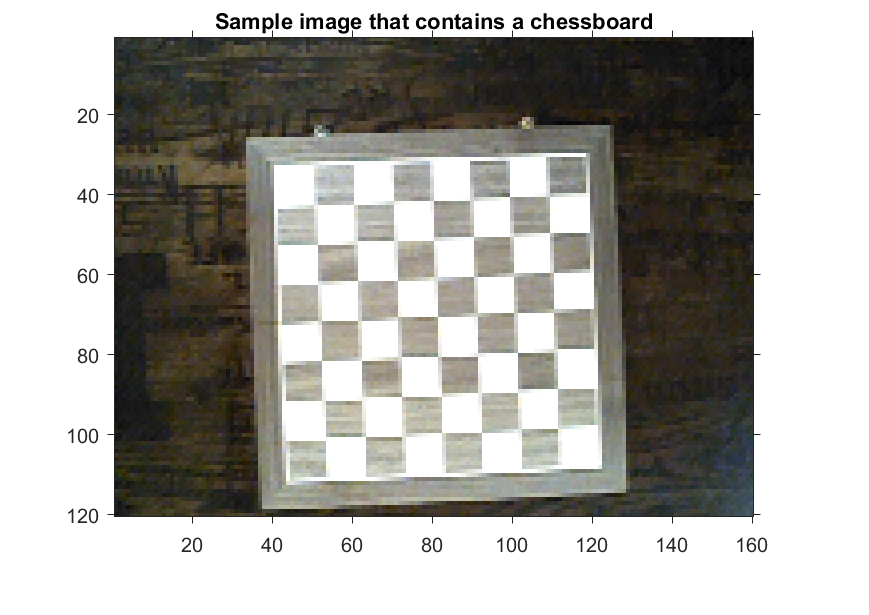

sampleImage = chessboardAlone1;
imshow(sampleImage);
title('Sample image that contains a chessboard');

## Segment out the entire chessboard for the sample image

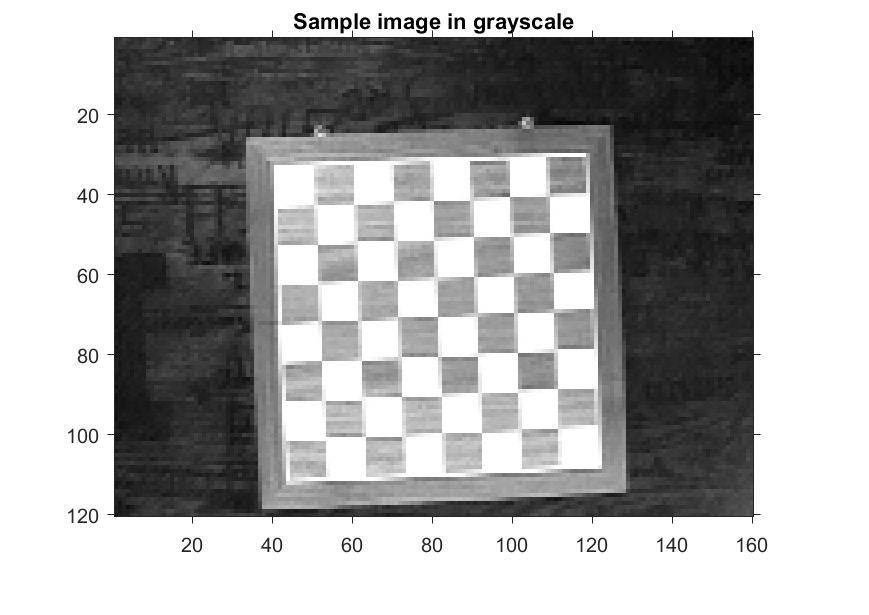

gray = rgb2gray(sampleImage);
imshow(gray);
title('Sample image in grayscale');

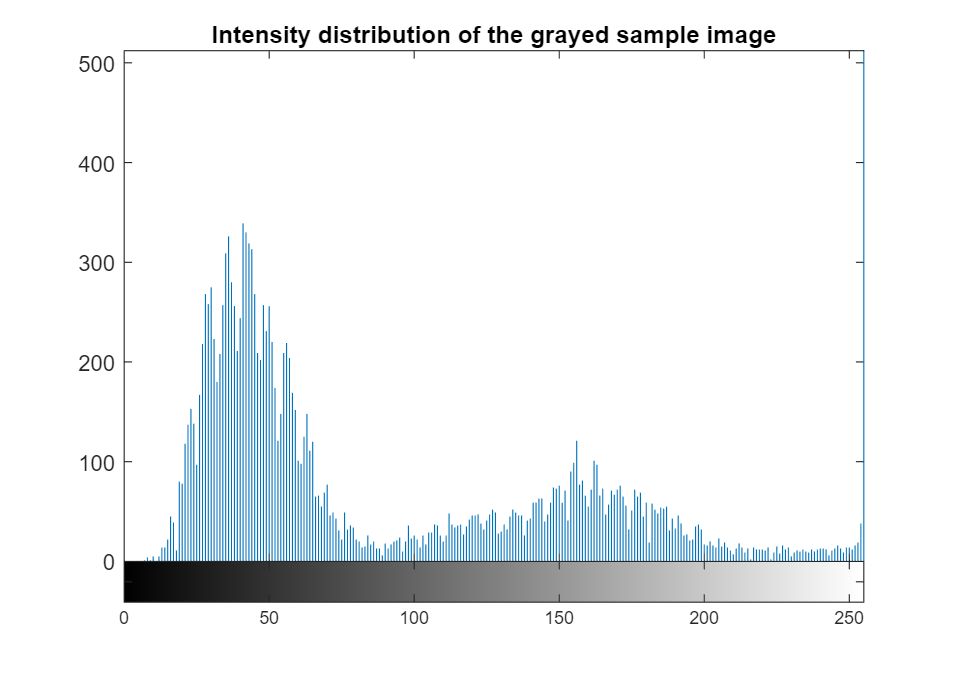


imhist(gray);
title('Intensity distribution of the grayed sample image');

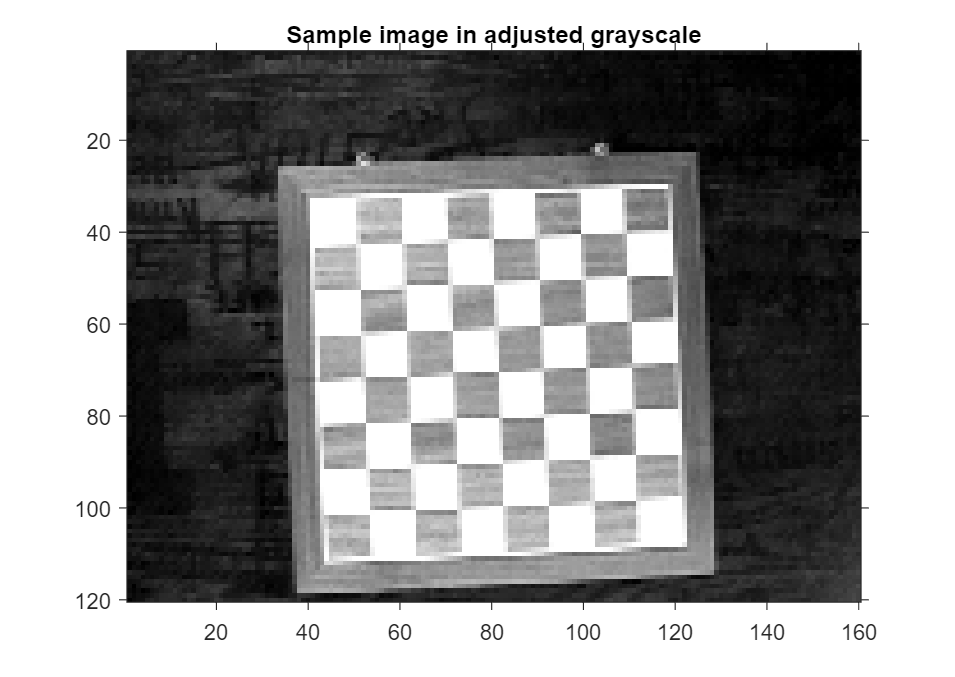


adjustedGray = imadjust(gray);
imshow(adjustedGray);
title('Sample image in adjusted grayscale');

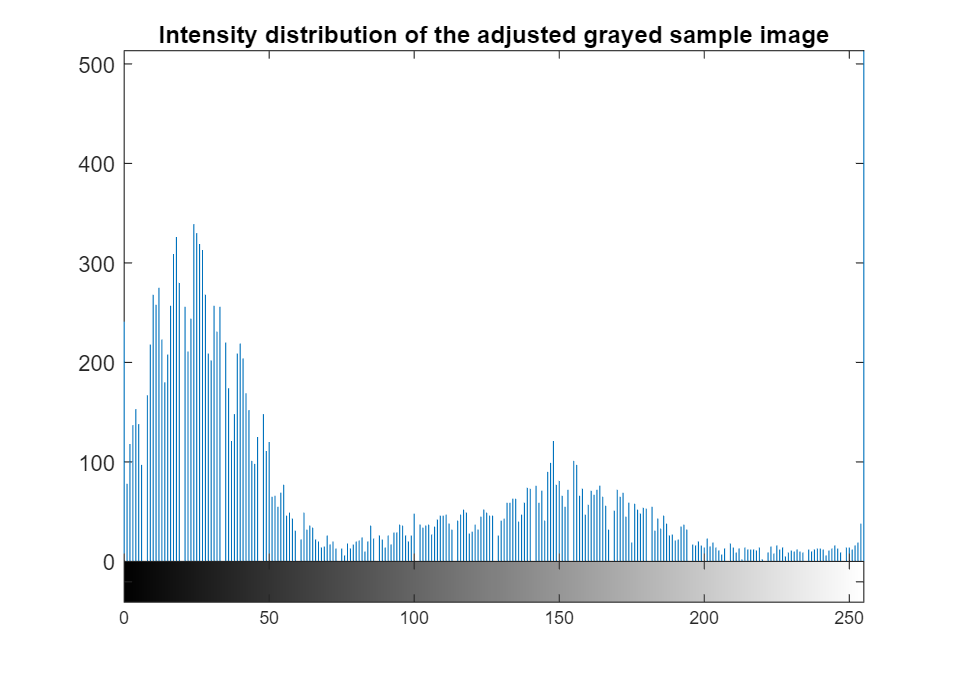


imhist(adjustedGray);
title('Intensity distribution of the adjusted grayed sample image');

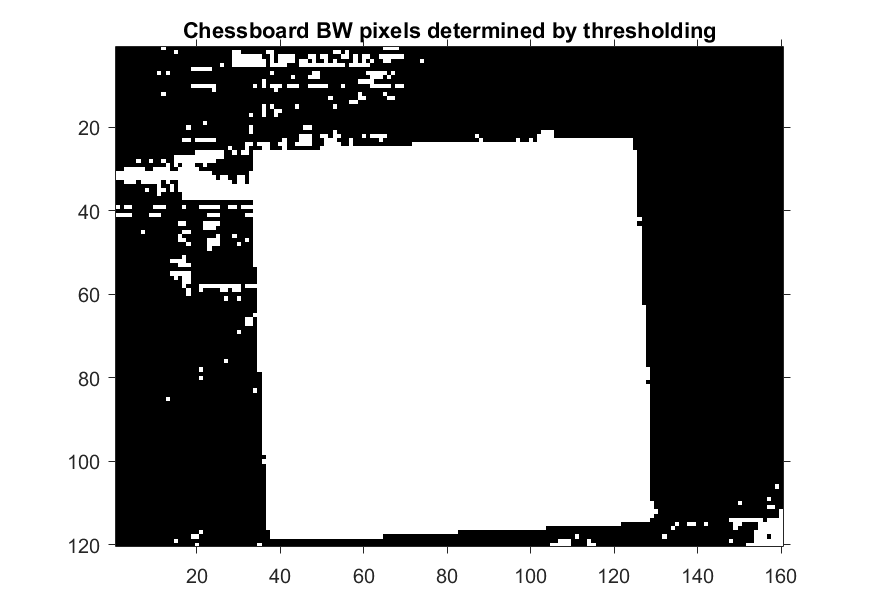


thresholdIntensity = round(mean(adjustedGray, 'all') - (1 / 2) * std(double(adjustedGray(:)), 0, 'all'));
chessboardPixelsBW = adjustedGray > thresholdIntensity;
imshow(chessboardPixelsBW);
title('Chessboard BW pixels determined by thresholding');

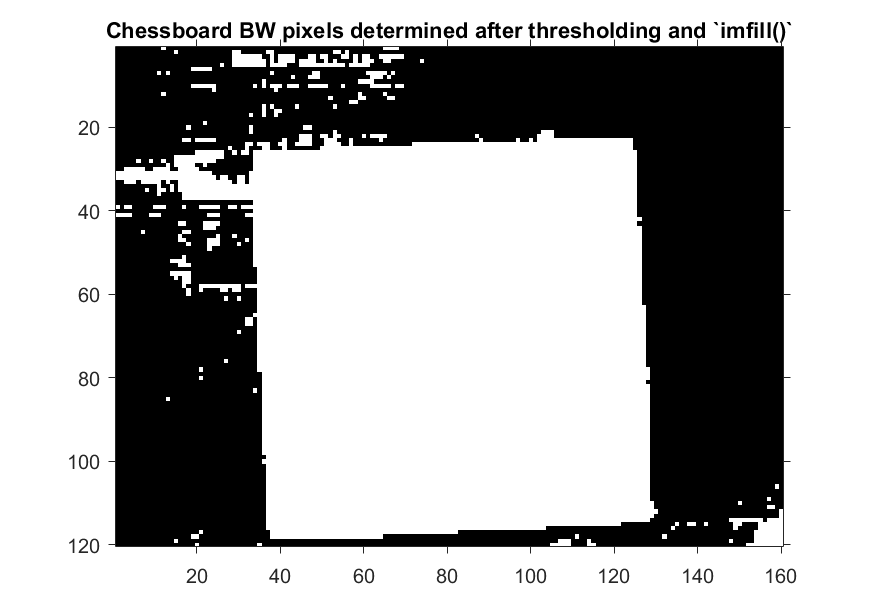


chessboardPixelsBW = imfill(chessboardPixelsBW, 'holes');
imshow(chessboardPixelsBW);
title('Chessboard BW pixels determined after thresholding and `imfill()`');


estimatedSquareWidth = sqrt(regionprops(bwpropfilt(chessboardPixelsBW, 'Area', 1), 'Area').Area) / 9

estimatedSquareWidth = 10.4633

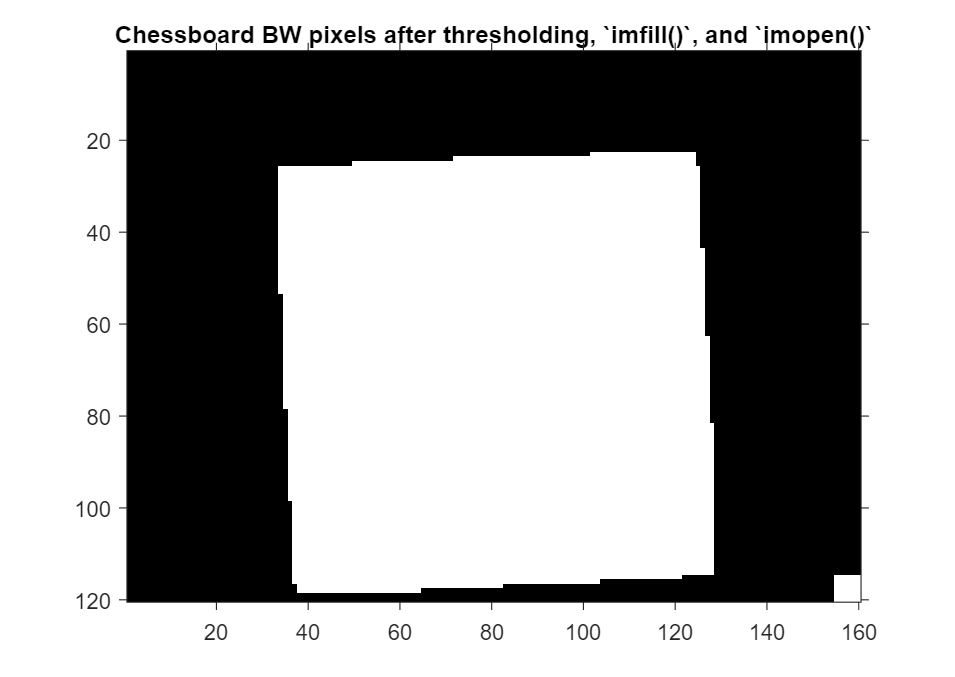

chessboardPixelsBW = imopen(chessboardPixelsBW, strel('square', round(estimatedSquareWidth)));

imshow(chessboardPixelsBW);
title('Chessboard BW pixels after thresholding, `imfill()`, and `imopen()`');

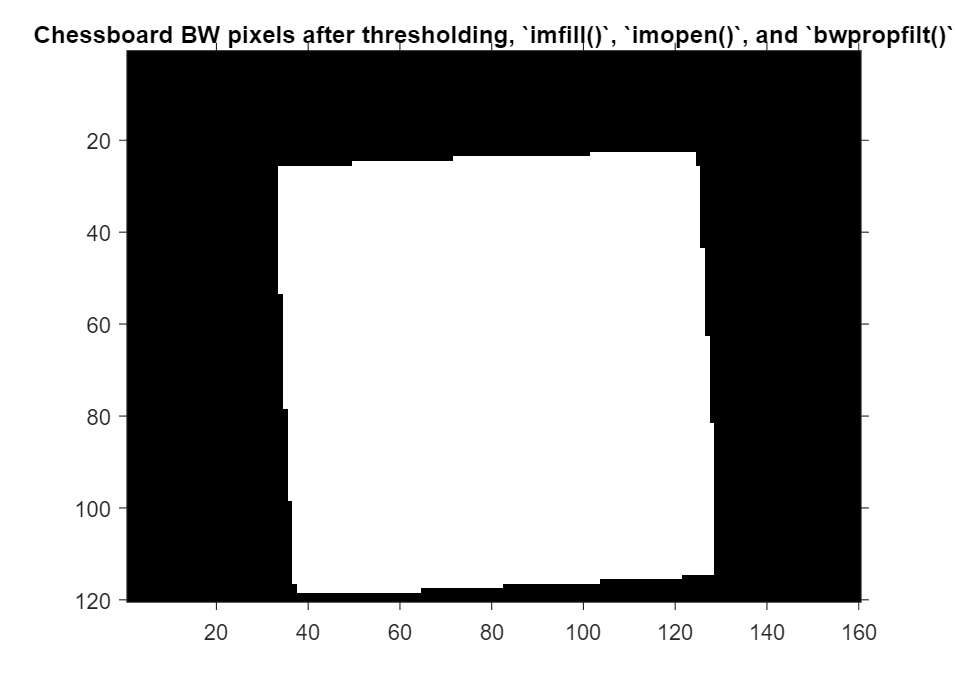


chessboardPixelsBW = bwpropfilt(chessboardPixelsBW, 'Area', 1);
imshow(chessboardPixelsBW);
title('Chessboard BW pixels after thresholding, `imfill()`, `imopen()`, and `bwpropfilt()`');

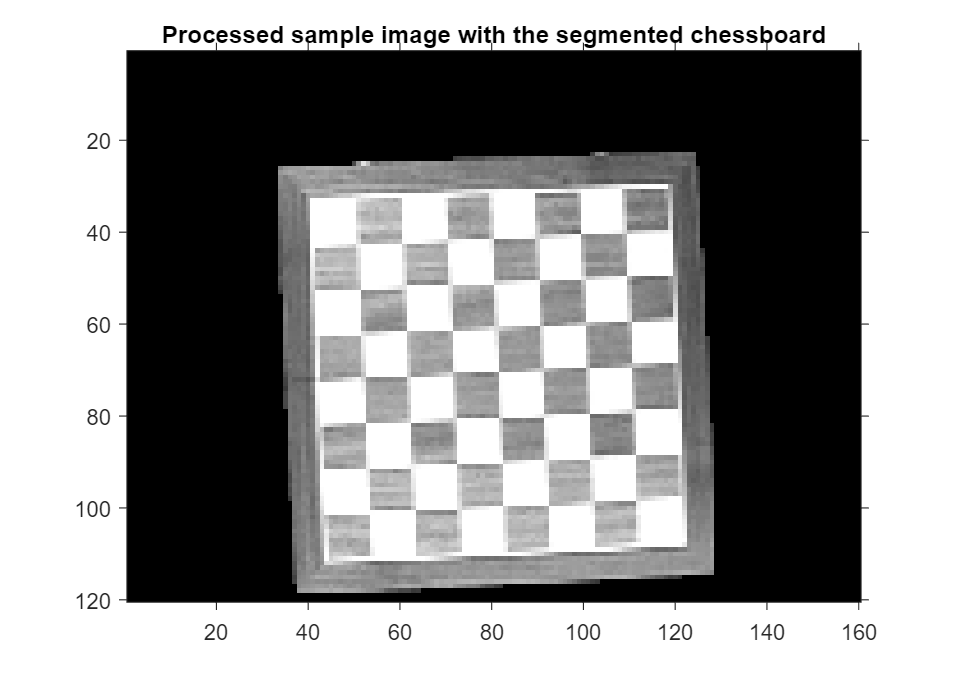


chessboardPixelsGray = adjustedGray .* uint8(chessboardPixelsBW);
imshow(chessboardPixelsGray);
title('Processed sample image with the segmented chessboard');

## Segment out the connected squares for the sample image

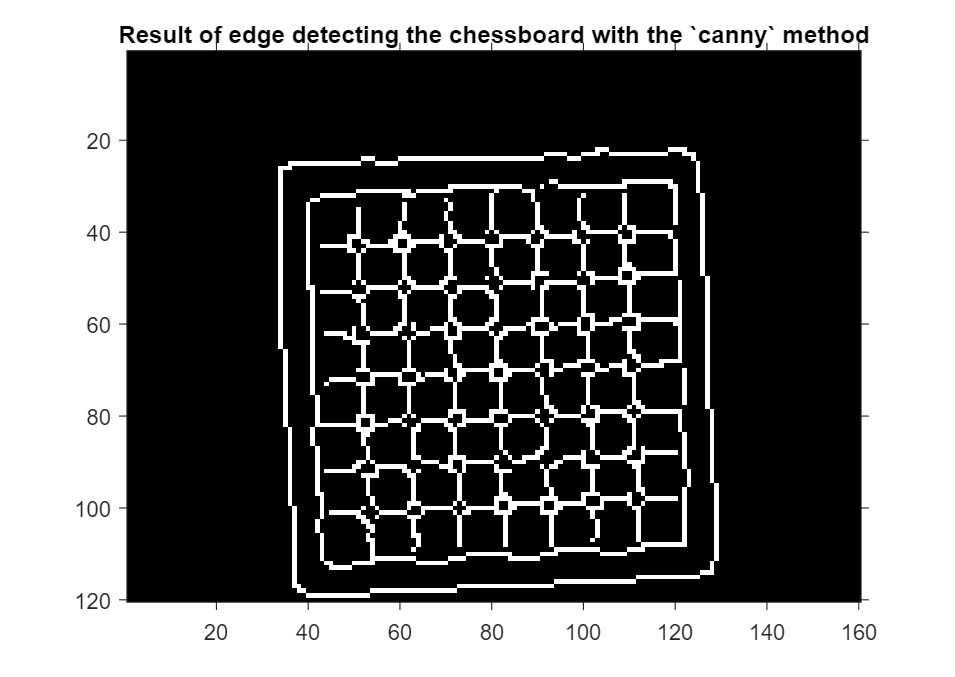

edgeDetectionResult = edge(chessboardPixelsGray, 'canny');
imshow(edgeDetectionResult);
title('Result of edge detecting the chessboard with the `canny` method');

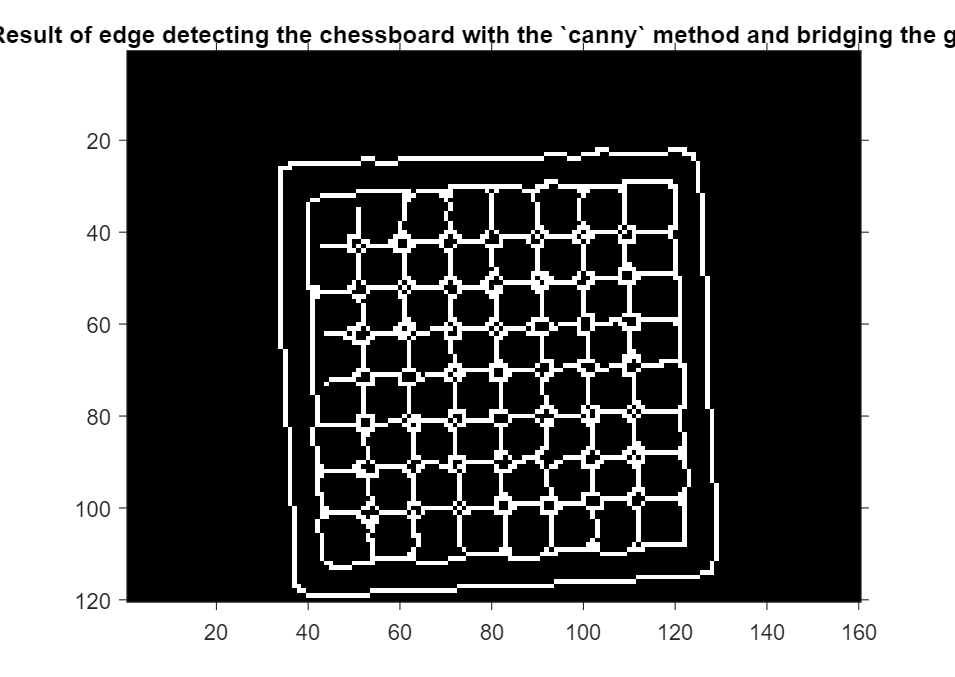


edgeDetectionResult = bwmorph(edgeDetectionResult, 'bridge');
imshow(edgeDetectionResult);
title('Result of edge detecting the chessboard with the `canny` method and bridging the gaps');

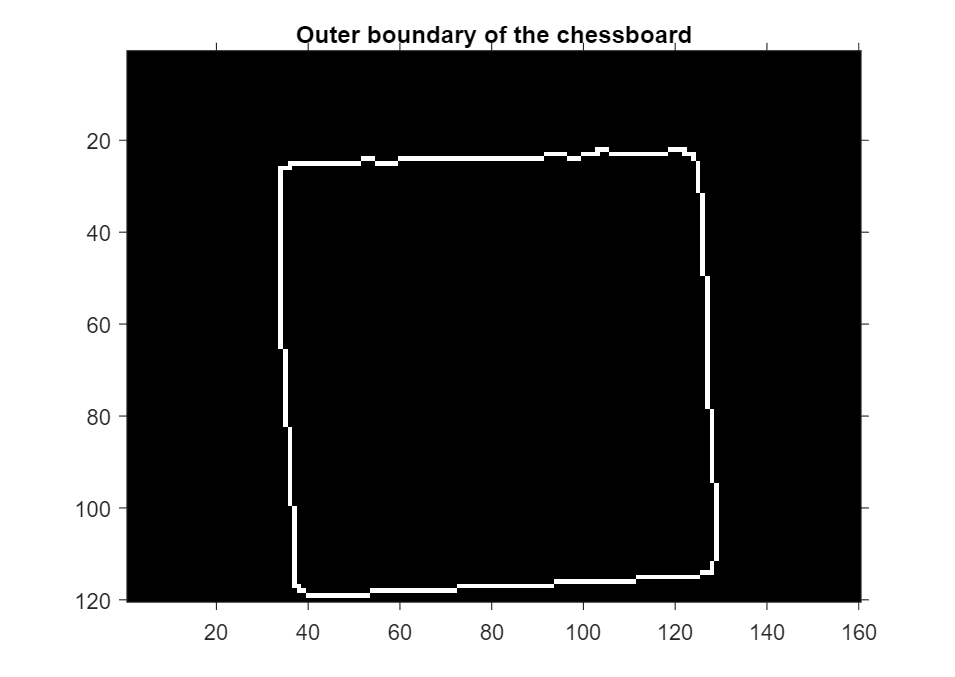


outerBoundary = bwpropfilt(edgeDetectionResult, 'ConvexArea', 1);
imshow(outerBoundary);
title('Outer boundary of the chessboard');

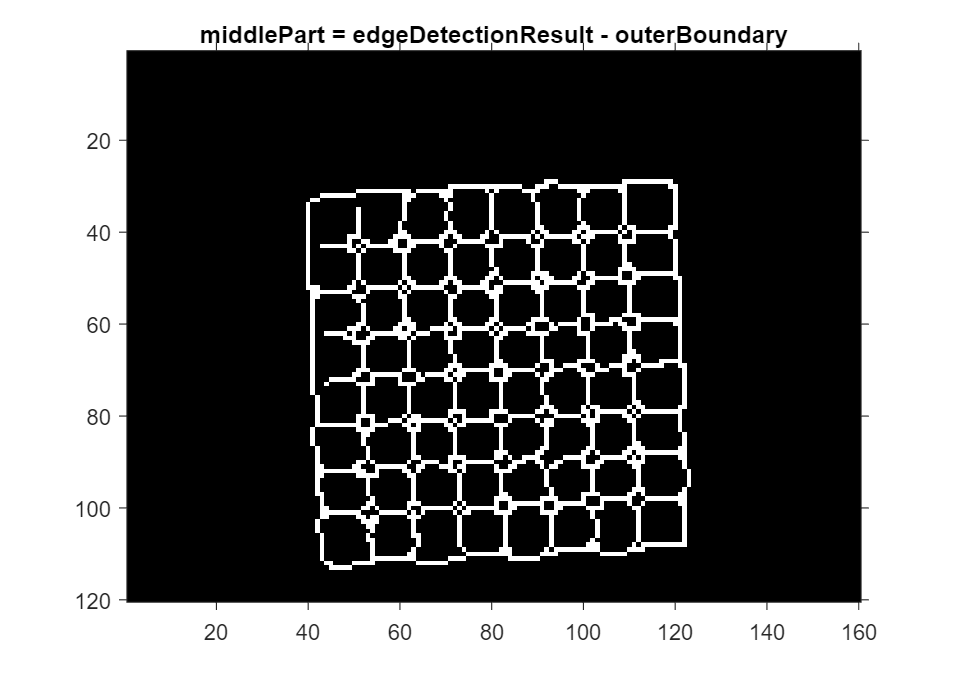


middlePart = edgeDetectionResult - outerBoundary;
imshow(middlePart);
title('middlePart = edgeDetectionResult - outerBoundary');

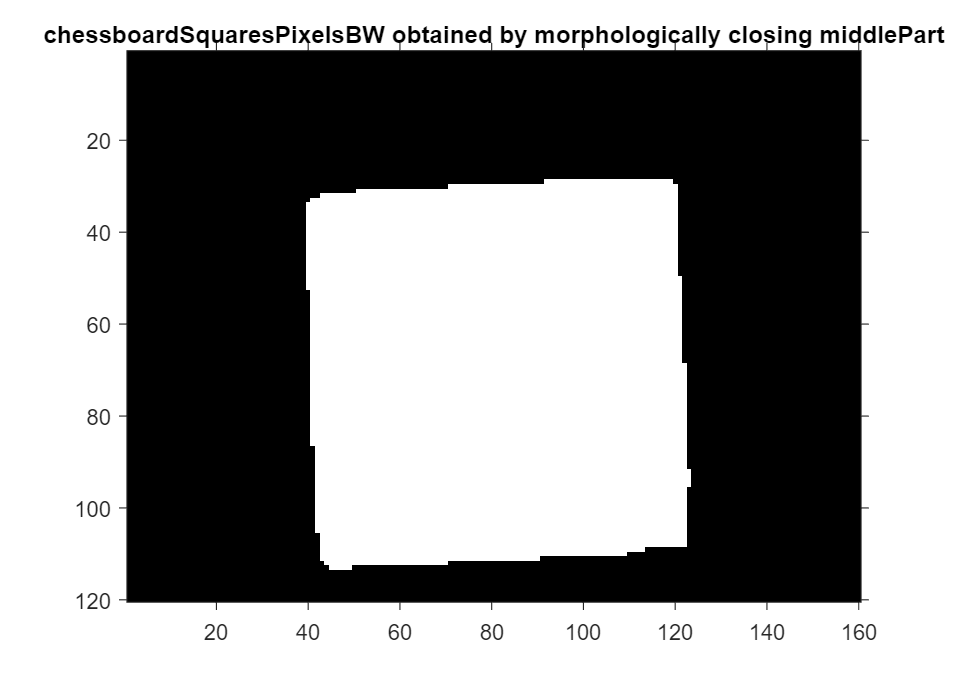


chessboardSquaresPixelsBW = imclose(middlePart, strel('square', 160));
imshow(chessboardSquaresPixelsBW);
title('chessboardSquaresPixelsBW obtained by morphologically closing middlePart')

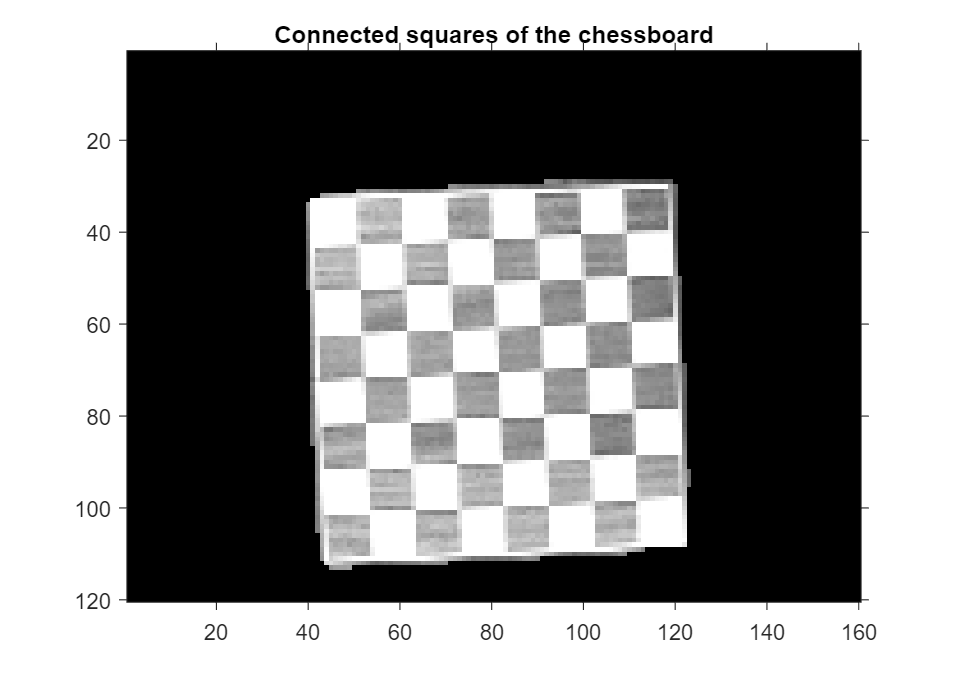


chessboardSquaresPixelsGray = uint8(chessboardSquaresPixelsBW) .* chessboardPixelsGray;
imshow(chessboardSquaresPixelsGray);
title('Connected squares of the chessboard');

## Separate the connected squares for the sample image

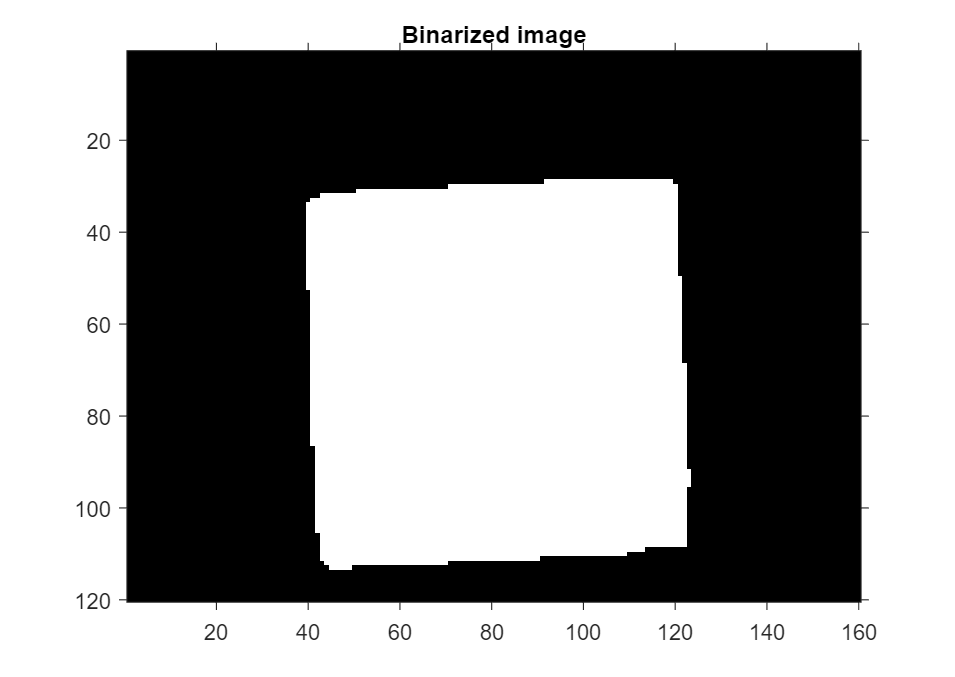

binarizedImage = imbinarize(chessboardSquaresPixelsGray, 0);
imshow(binarizedImage);
title('Binarized image');

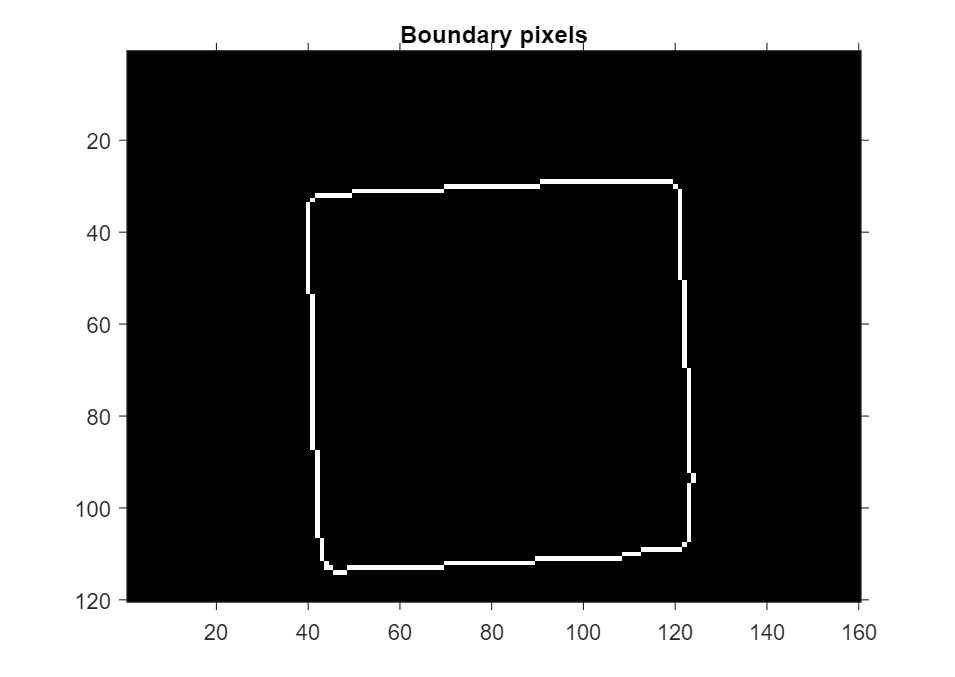


boundaryPixels = edge(binarizedImage, 'sobel');
imshow(boundaryPixels);
title('Boundary pixels');


estimatedPerimeter = regionprops(boundaryPixels, 'Perimeter').Perimeter;
estimatedSquareWidth = estimatedPerimeter / 4 / 8

estimatedSquareWidth = 9.8365

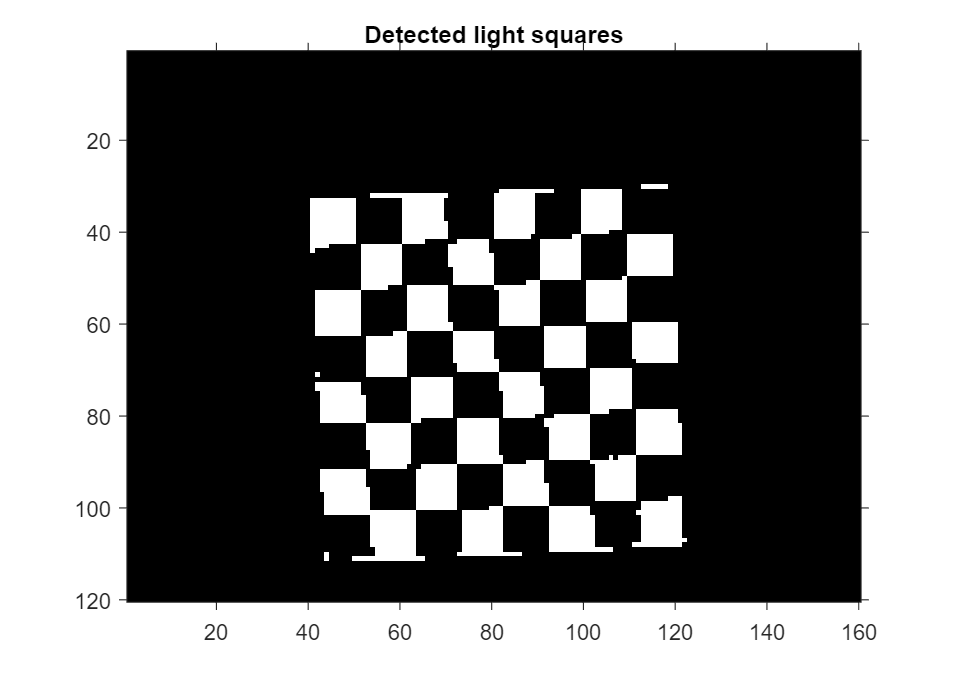


detectedLightSquares = chessboardSquaresPixelsGray > 250; % the threshold value could be anything between 200 and 250
imshow(detectedLightSquares);
title('Detected light squares');

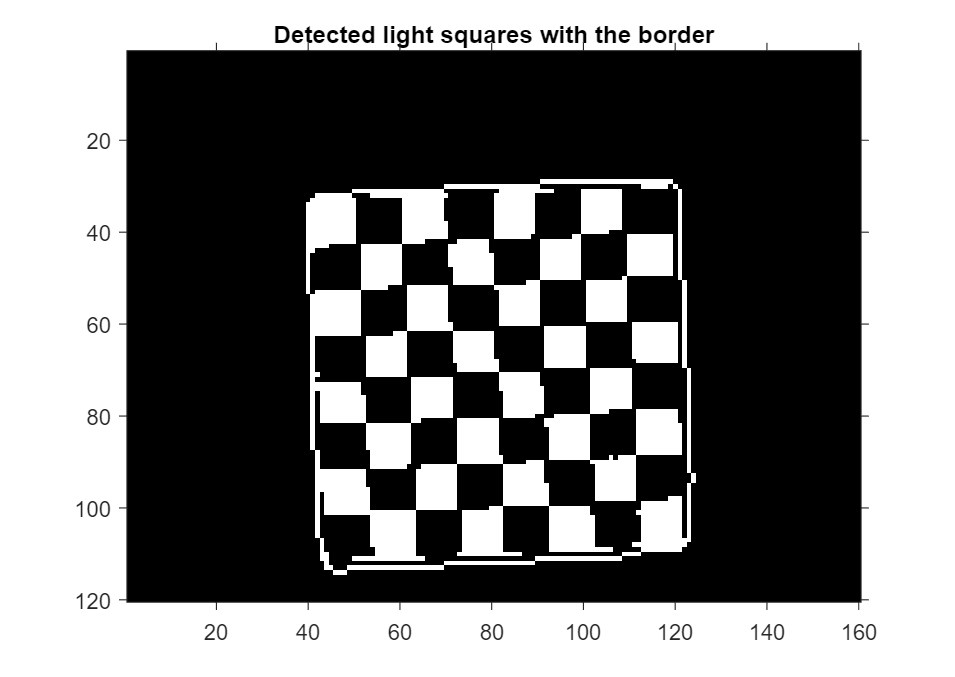


lightSquaresWithBorder = detectedLightSquares;
lightSquaresWithBorder(boundaryPixels) = 1;
imshow(lightSquaresWithBorder);
title('Detected light squares with the border');

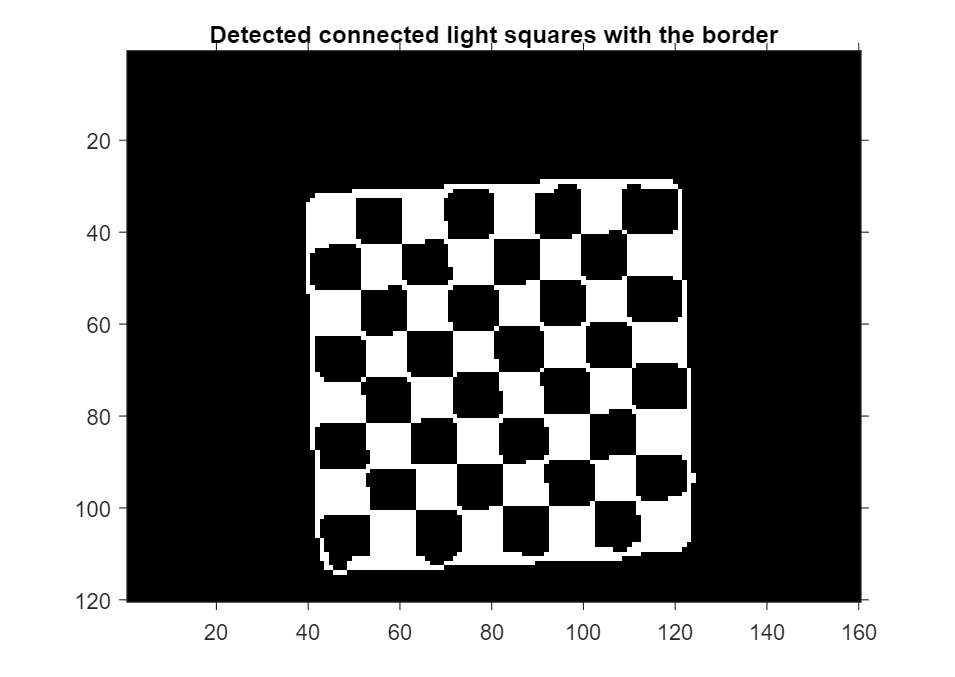


lightSquaresBorderedAndConnected = bwmorph(lightSquaresWithBorder, 'bridge');
lightSquaresBorderedAndConnected = imclose(lightSquaresBorderedAndConnected, strel('square', round(estimatedSquareWidth / 3)));
imshow(lightSquaresBorderedAndConnected);
title('Detected connected light squares with the border');

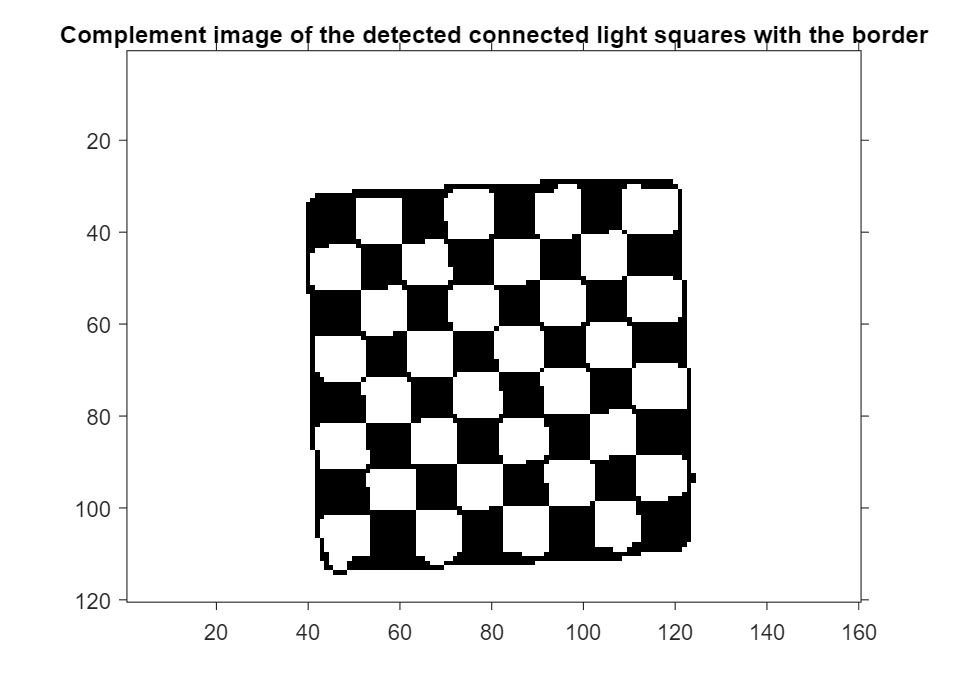


lightSquaresBorderedConnectedAndComplemented = imcomplement(lightSquaresBorderedAndConnected);
imshow(lightSquaresBorderedConnectedAndComplemented);
title('Complement image of the detected connected light squares with the border');

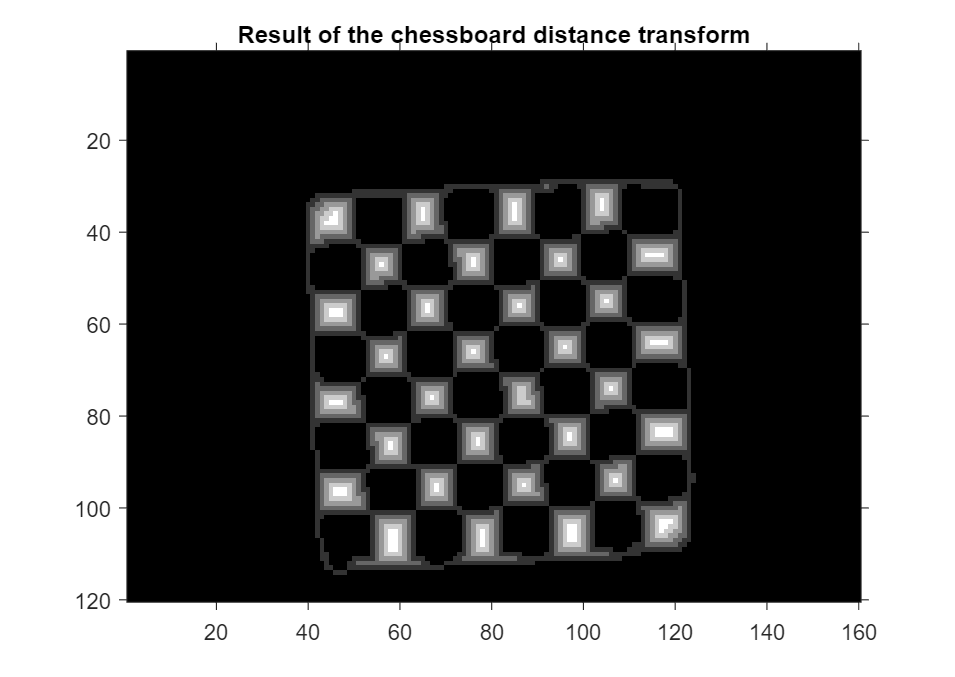


distanceTransform = rescale(bwdist(lightSquaresBorderedConnectedAndComplemented, 'chessboard'));
imshow(distanceTransform);
title('Result of the chessboard distance transform');

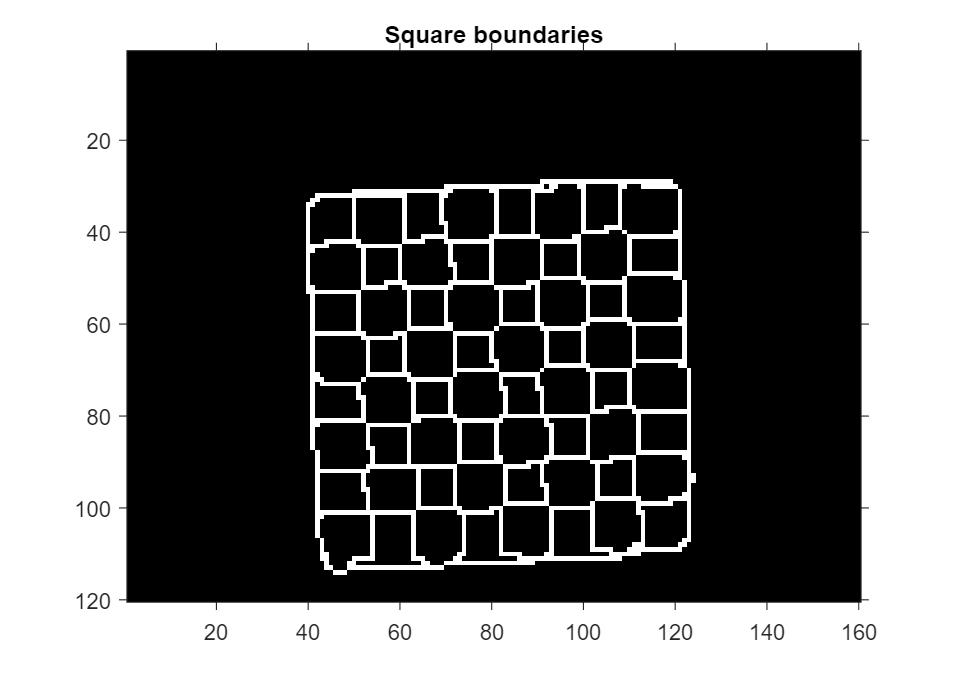


squareBoundaries = distanceTransform > 0 & distanceTransform < 0.3;
squareBoundaries(boundaryPixels) = 1;
imshow(squareBoundaries);
title('Square boundaries');

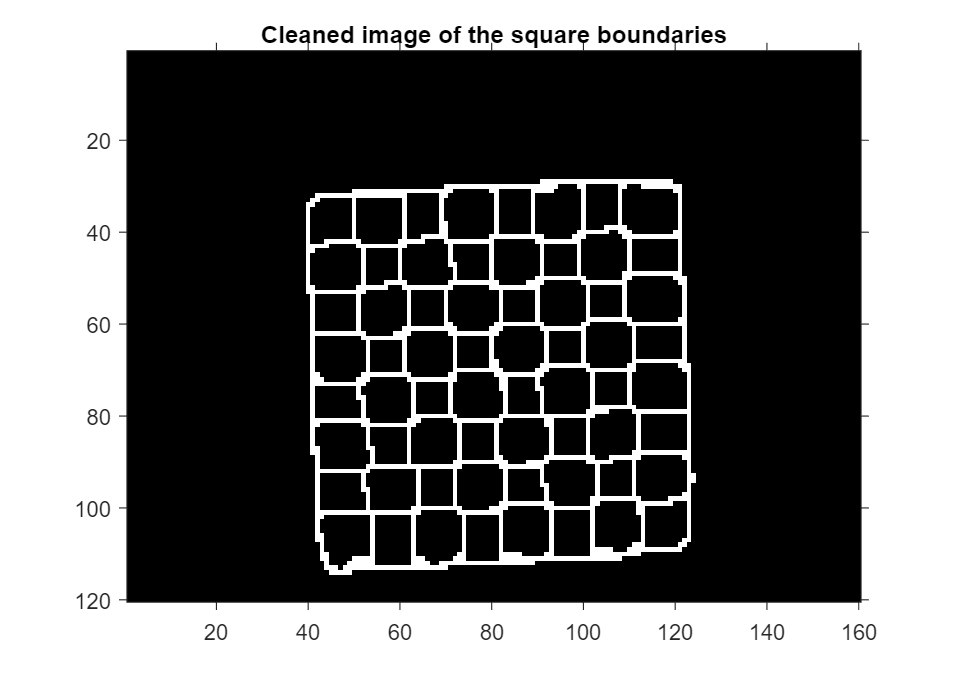


squareBoundariesCleaned = imclose(squareBoundaries, strel('square', round(estimatedSquareWidth / 3)));
squareBoundariesCleaned = bwmorph(squareBoundariesCleaned, 'diag');
imshow(squareBoundariesCleaned);
title('Cleaned image of the square boundaries');

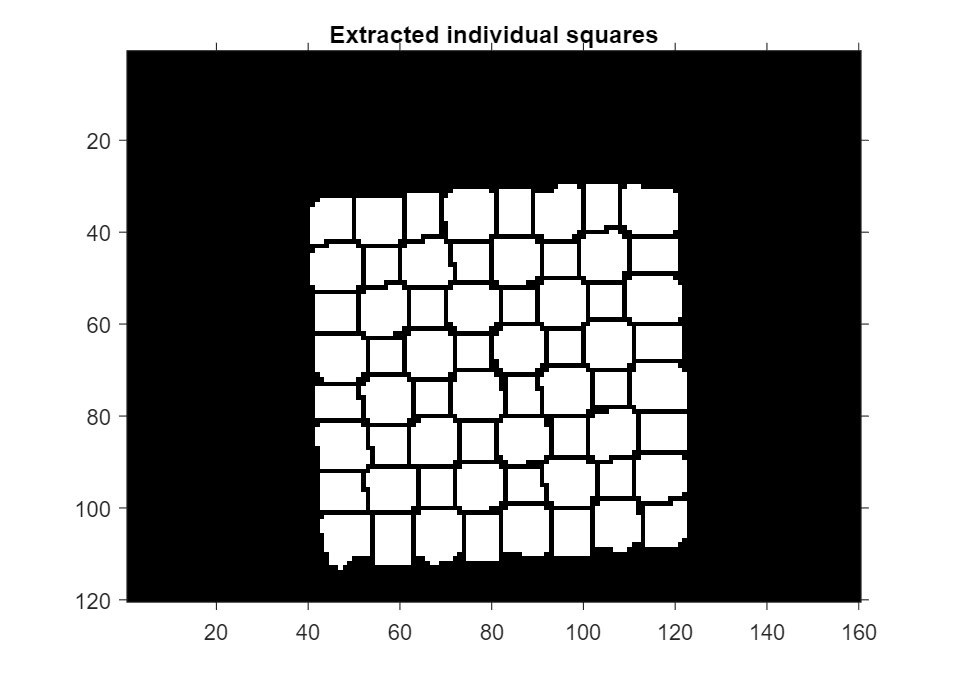


allIndividualSquares = imcomplement(squareBoundariesCleaned) .* imfill(squareBoundariesCleaned, 'holes');
allIndividualSquares = logical(allIndividualSquares);
imshow(allIndividualSquares);
title('Extracted individual squares');

allIndividualSquaresStats = regionprops('table', allIndividualSquares, 'Centroid')

allIndividualSquaresStats = 64×1 table
        Centroid    
    ________________

    45.025    37.321
    46.137    47.667
        46      57.5
    46.951    67.301
    46.299     77.09
    47.406    86.538
    47.263    96.605
    48.216    106.45
      55.5    37.408
    56.515    57.155
    57.388    76.459
    55.887    47.302
    58.272    95.891
        57        67
    57.733    86.367
      58.5       107


## Determine and label the chessboard coordinates for the sample image

allIndividualSquaresStats.x = allIndividualSquaresStats.Centroid(:, 1);
allIndividualSquaresStats.y = allIndividualSquaresStats.Centroid(:, 2);
allIndividualSquaresStats

allIndividualSquaresStats = 64×3 table
        Centroid          x         y   
    ________________    ______    ______

    45.025    37.321    45.025    37.321
    46.137    47.667    46.137    47.667
        46      57.5        46      57.5
    46.951    67.301    46.951    67.301
    46.299     77.09    46.299     77.09
    47.406    86.538    47.406    86.538
    47.263    96.605    47.263    96.605
    48.216    106.45    48.216    106.45
      55.5    37.408      55.5    37.408
    56.515    57.155    56.515    57.155
    57.388    76.459    57.388    76.459
    55.887    47.302    55.887    47.302
    58.272    95.891    58.272    95.891
        57        67        57        67
    57.733    86.367    57.733    86.367
      58.5       107      58.5       107



allIndividualSquaresStats = sortrows(allIndividualSquaresStats, 'x');

for i = 1 : size(allIndividualSquaresStats, 1)
    allIndividualSquaresStats{i, 'x'} = idivide(i - 1, int8(8));
end
allIndividualSquaresStats

allIndividualSquaresStats = 64×3 table
        Centroid        x      y   
    ________________    _    ______

    45.025    37.321    0    37.321
        46      57.5    0      57.5
    46.137    47.667    0    47.667
    46.299     77.09    0     77.09
    46.951    67.301    0    67.301
    47.263    96.605    0    96.605
    47.406    86.538    0    86.538
    48.216    106.45    0    106.45
      55.5    37.408    1    37.408
    55.887    47.302    1    47.302
    56.515    57.155    1    57.155
        57        67    1        67
    57.388    76.459    1    76.459
    57.733    86.367    1    86.367
    58.272    95.891    1    95.891
      58.5       107    1       107



allIndividualSquaresStats = sortrows(allIndividualSquaresStats, ["x", "y"], ["ascend", "descend"]);
allIndividualSquaresStats

allIndividualSquaresStats = 64×3 table
        Centroid        x      y   
    ________________    _    ______

    48.216    106.45    0    106.45
    47.263    96.605    0    96.605
    47.406    86.538    0    86.538
    46.299     77.09    0     77.09
    46.951    67.301    0    67.301
        46      57.5    0      57.5
    46.137    47.667    0    47.667
    45.025    37.321    0    37.321
      58.5       107    1       107
    58.272    95.891    1    95.891
    57.733    86.367    1    86.367
    57.388    76.459    1    76.459
        57        67    1        67
    56.515    57.155    1    57.155
    55.887    47.302    1    47.302
      55.5    37.408    1    37.408



for i = 1 : size(allIndividualSquaresStats, 1)
    allIndividualSquaresStats{i, 'y'} = mod(i - 1, 8);
end
allIndividualSquaresStats

allIndividualSquaresStats = 64×3 table
        Centroid        x    y
    ________________    _    _

    48.216    106.45    0    0
    47.263    96.605    0    1
    47.406    86.538    0    2
    46.299     77.09    0    3
    46.951    67.301    0    4
        46      57.5    0    5
    46.137    47.667    0    6
    45.025    37.321    0    7
      58.5       107    1    0
    58.272    95.891    1    1
    57.733    86.367    1    2
    57.388    76.459    1    3
        57        67    1    4
    56.515    57.155    1    5
    55.887    47.302    1    6
      55.5    37.408    1    7



ranks = ["a", "b", "c", "d", "e", "f", "g", "h"];
files = ["1", "2", "3", "4", "5", "6", "7", "8"];
coordinates = strings(8);
for i = 1 : 8
    for j = 1 : 8
        coordinates(j, i) = ranks(i) + files(j);
    end
end
coordinates

coordinates = 8×8 string array
    "a1"    "b1"    "c1"    "d1"    "e1"    "f1"    "g1"    "h1"
    "a2"    "b2"    "c2"    "d2"    "e2"    "f2"    "g2"    "h2"
    "a3"    "b3"    "c3"    "d3"    "e3"    "f3"    "g3"    "h3"
    "a4"    "b4"    "c4"    "d4"    "e4"    "f4"    "g4"    "h4"
    "a5"    "b5"    "c5"    "d5"    "e5"    "f5"    "g5"    "h5"
    "a6"    "b6"    "c6"    "d6"    "e6"    "f6"    "g6"    "h6"
    "a7"    "b7"    "c7"    "d7"    "e7"    "f7"    "g7"    "h7"
    "a8"    "b8"    "c8"    "d8"    "e8"    "f8"    "g8"    "h8"



allIndividualSquaresStats.Coordinates = coordinates(:);
allIndividualSquaresStats

allIndividualSquaresStats = 64×4 table
        Centroid        x    y    Coordinates
    ________________    _    _    ___________

    48.216    106.45    0    0       "a1"    
    47.263    96.605    0    1       "a2"    
    47.406    86.538    0    2       "a3"    
    46.299     77.09    0    3       "a4"    
    46.951    67.301    0    4       "a5"    
        46      57.5    0    5       "a6"    
    46.137    47.667    0    6       "a7"    
    45.025    37.321    0    7       "a8"    
      58.5       107    1    0       "b1"    
    58.272    95.891    1    1       "b2"    
    57.733    86.367    1    2       "b3"    
    57.388    76.459    1    3       "b4"    
        57        67    1    4       "b5"    
    56.515    57.155    1    5       "b6"    
    55.887    47.302    1    6       "b7"    
      55.5    37.408    1    7       "b8" 

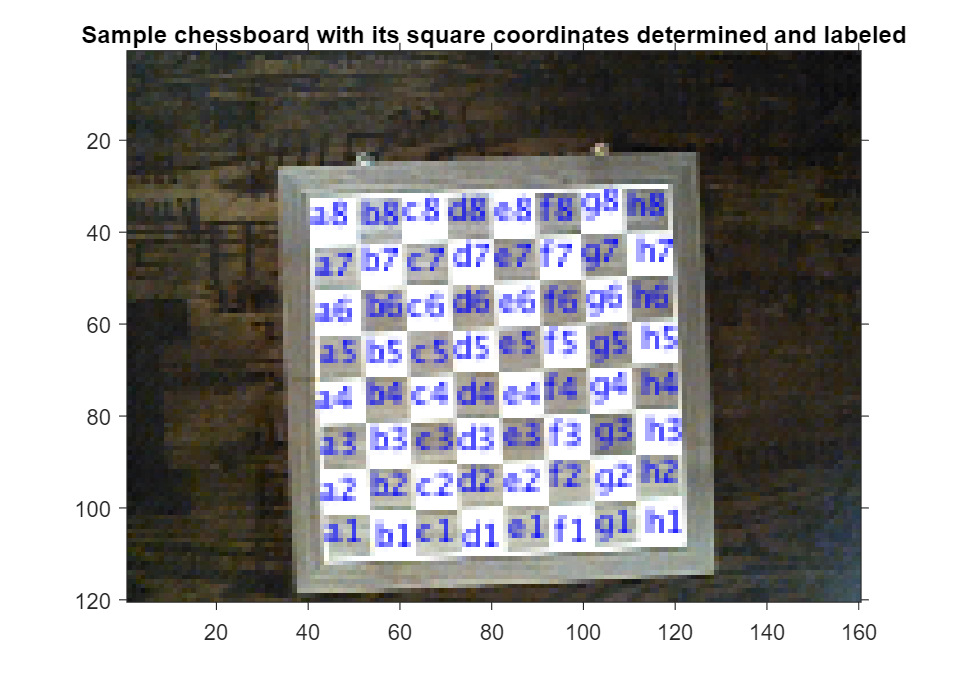


sampleChessboardWithSquaresCoordinatesDetermined = insertText(sampleImage, allIndividualSquaresStats.Centroid, ...
                                                   allIndividualSquaresStats.Coordinates, 'BoxOpacity', 0, ...
                                                   'TextColor', 'blue', 'AnchorPoint', 'Center', 'FontSize', 7);

imshow(sampleChessboardWithSquaresCoordinatesDetermined);
title('Sample chessboard with its square coordinates determined and labeled');

## Demonstrate the performance on a variety of data

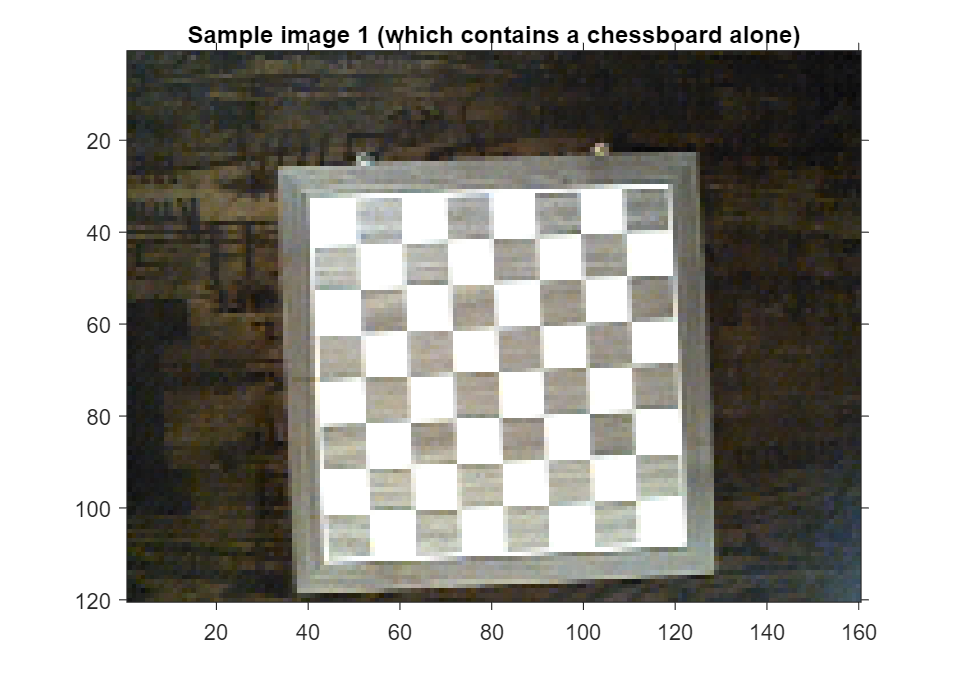

imshow(chessboardAlone1);
title('Sample image 1 (which contains a chessboard alone)');

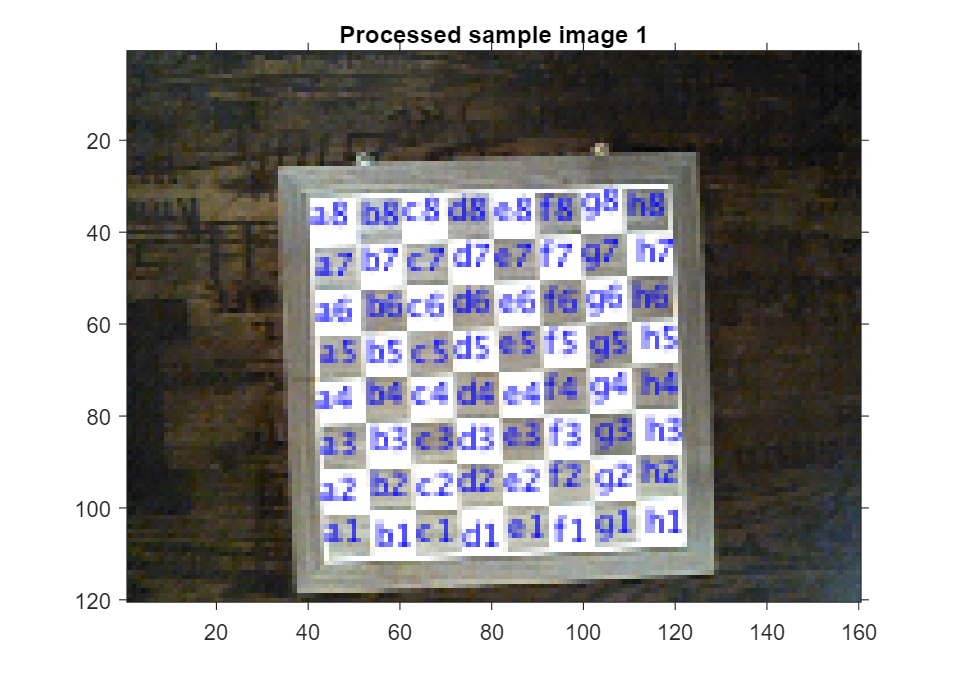

outputImage = chessboardProcessor(chessboardAlone1(:, :, 1), chessboardAlone1(:, :, 2), chessboardAlone1(:, :, 3));
imshow(outputImage);
title('Processed sample image 1');

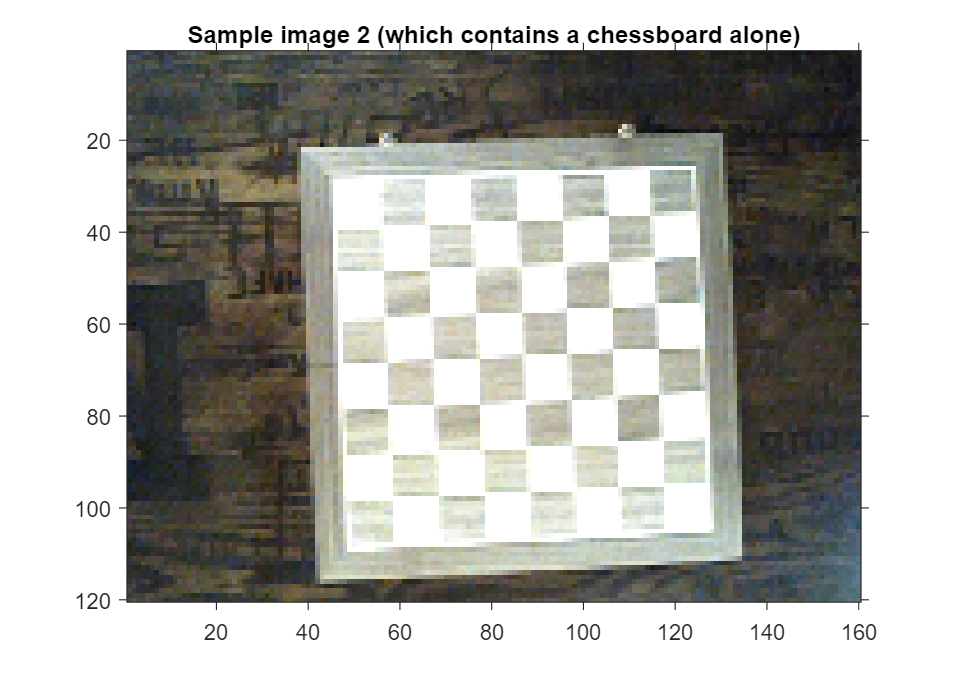


imshow(chessboardAlone2);
title('Sample image 2 (which contains a chessboard alone)');

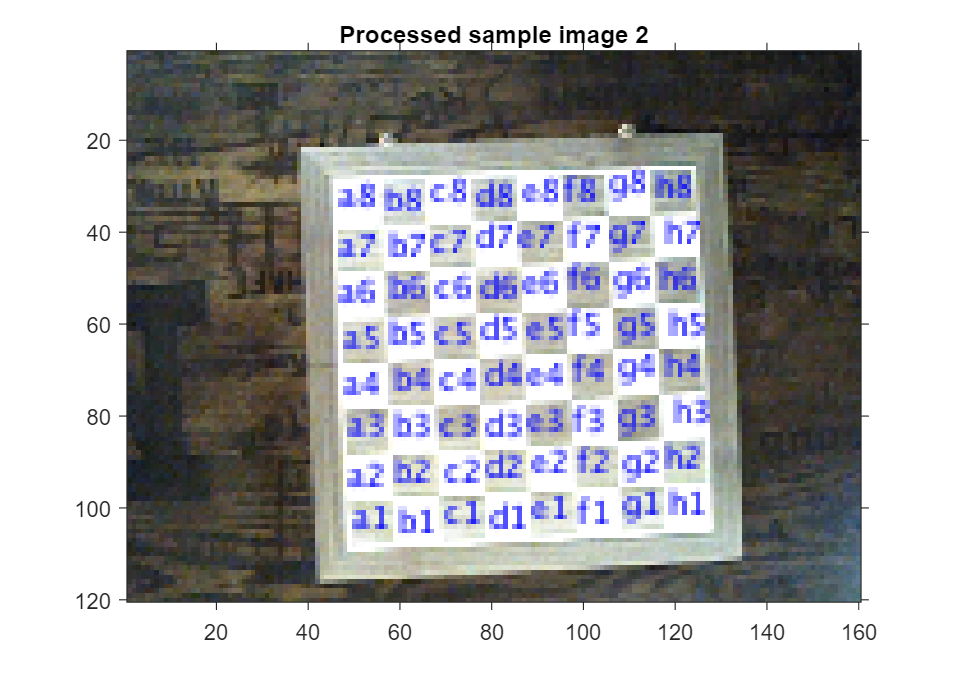

outputImage = chessboardProcessor(chessboardAlone2(:, :, 1), chessboardAlone2(:, :, 2), chessboardAlone2(:, :, 3));
imshow(outputImage);
title('Processed sample image 2');

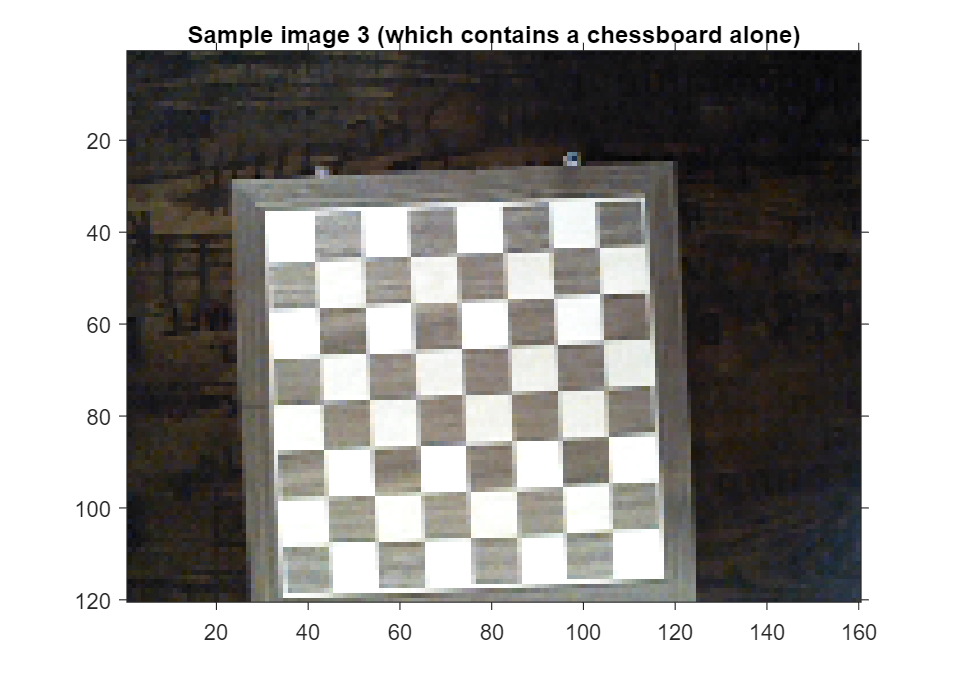


imshow(chessboardAlone3);
title('Sample image 3 (which contains a chessboard alone)');

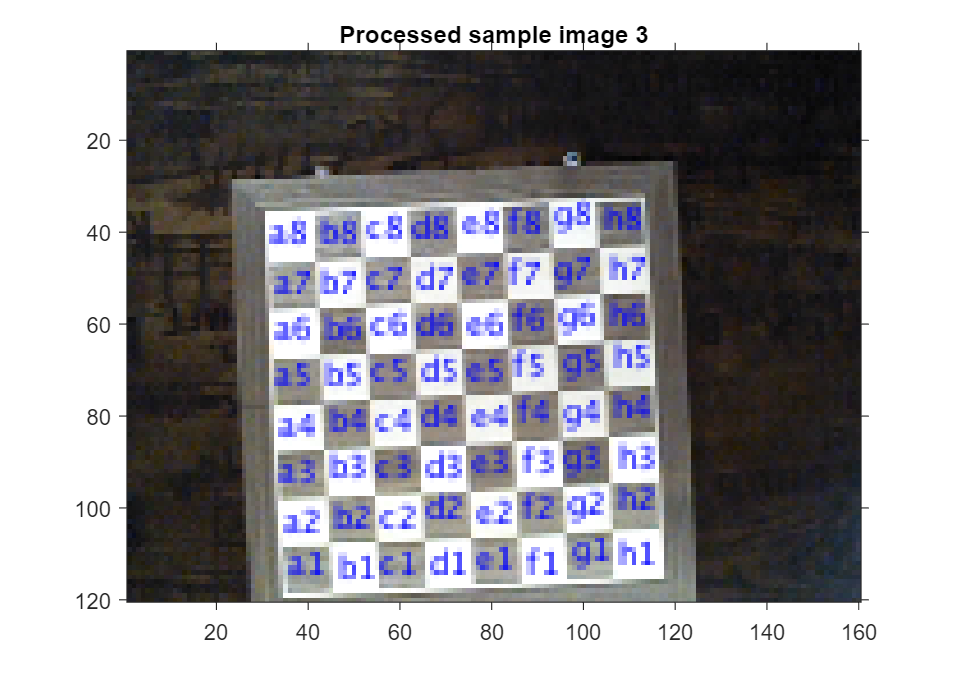

outputImage = chessboardProcessor(chessboardAlone3(:, :, 1), chessboardAlone3(:, :, 2), chessboardAlone3(:, :, 3));
imshow(outputImage);
title('Processed sample image 3');

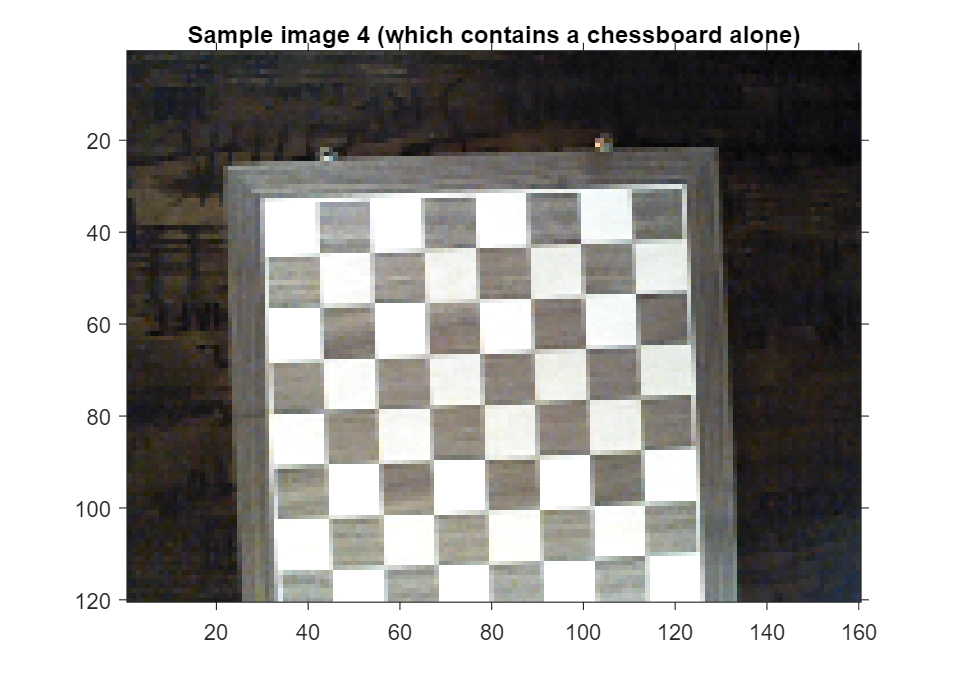


imshow(chessboardAlone4);
title('Sample image 4 (which contains a chessboard alone)');

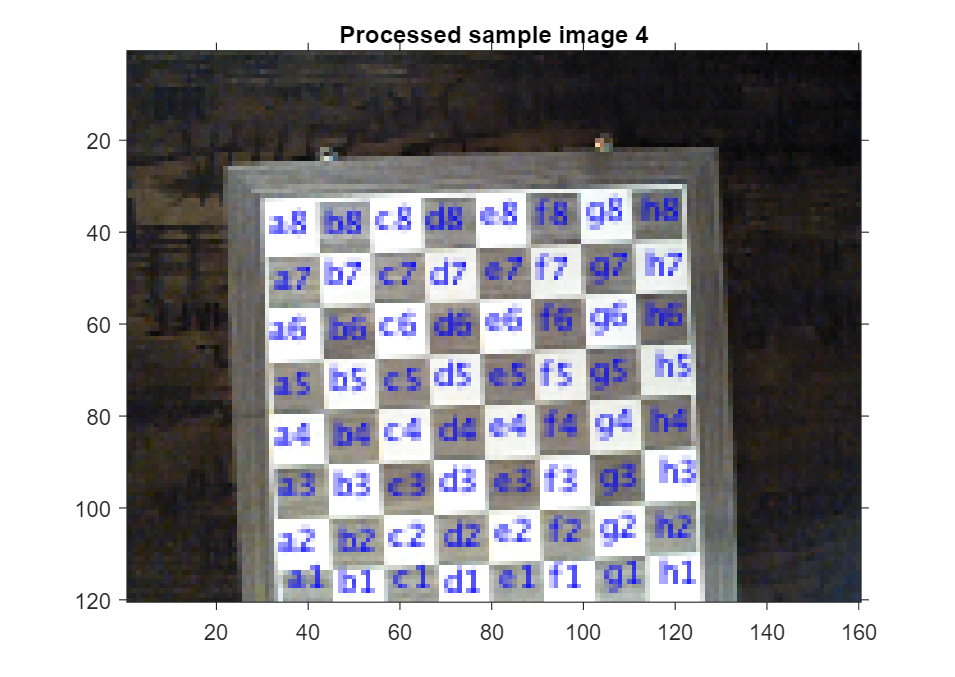

outputImage = chessboardProcessor(chessboardAlone4(:, :, 1), chessboardAlone4(:, :, 2), chessboardAlone4(:, :, 3));
imshow(outputImage);
title('Processed sample image 4');

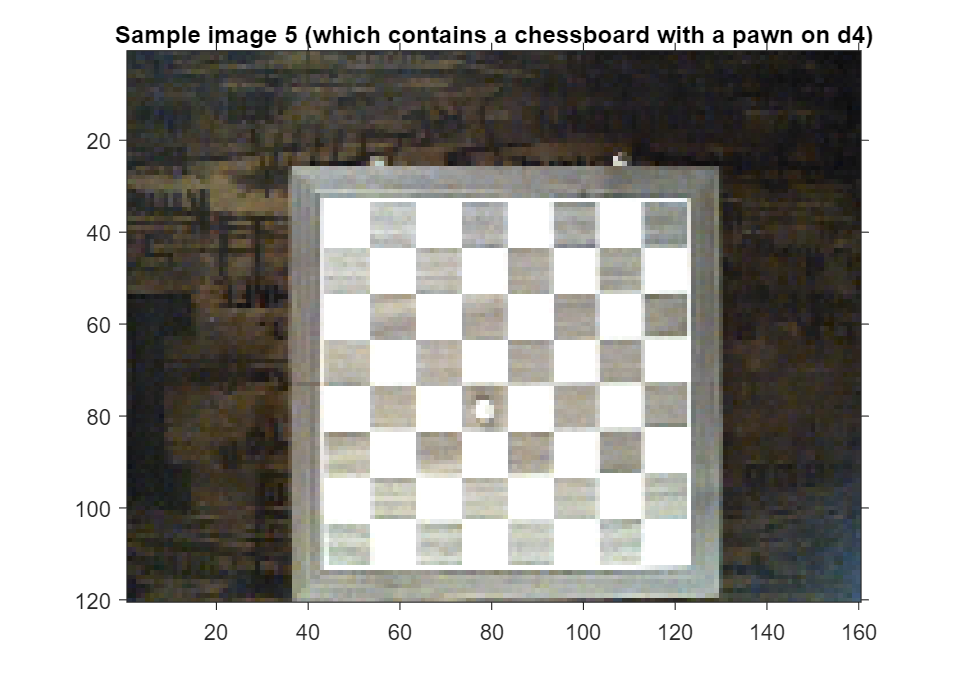


imshow(chessboardwithpawnd4_1);
title('Sample image 5 (which contains a chessboard with a pawn on d4)');

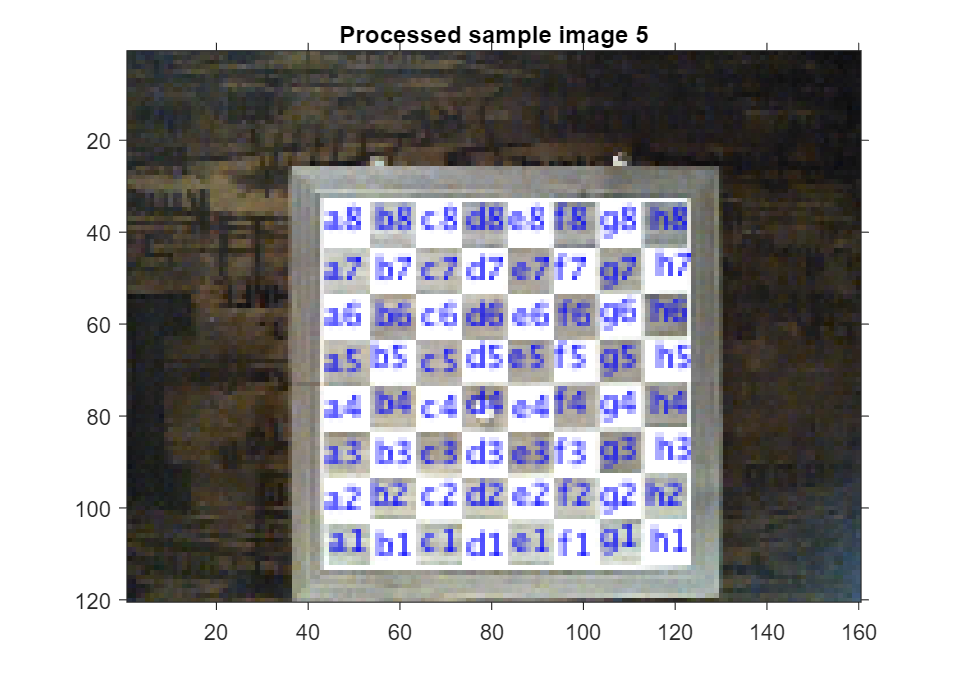

outputImage = chessboardProcessor(chessboardwithpawnd4_1(:, :, 1), chessboardwithpawnd4_1(:, :, 2), chessboardwithpawnd4_1(:, :, 3));
imshow(outputImage);
title('Processed sample image 5');

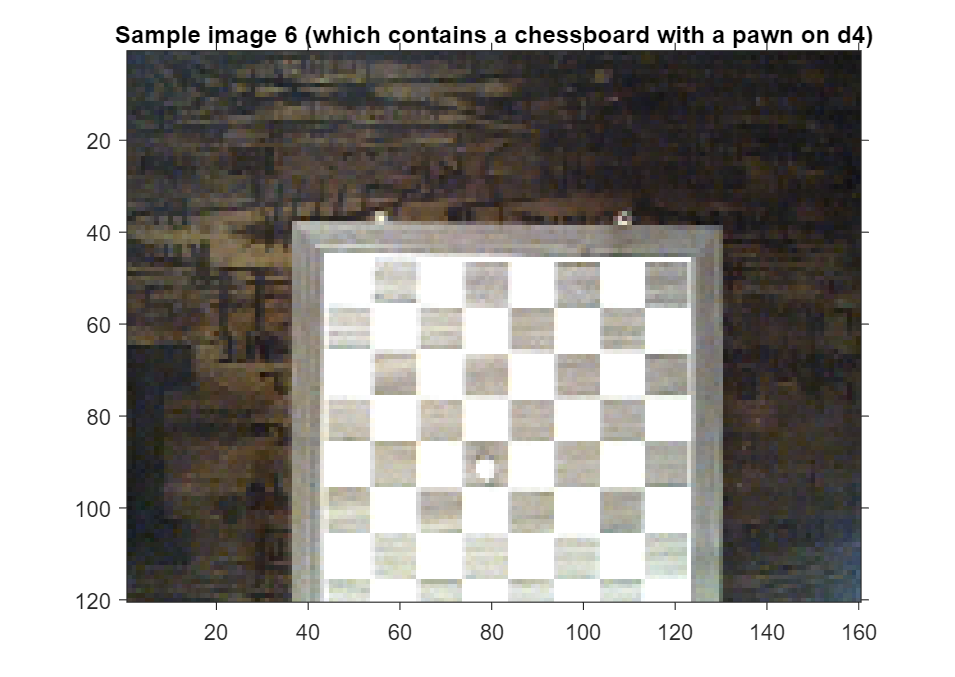


imshow(chessboardwithpawnd4_2);
title('Sample image 6 (which contains a chessboard with a pawn on d4)');

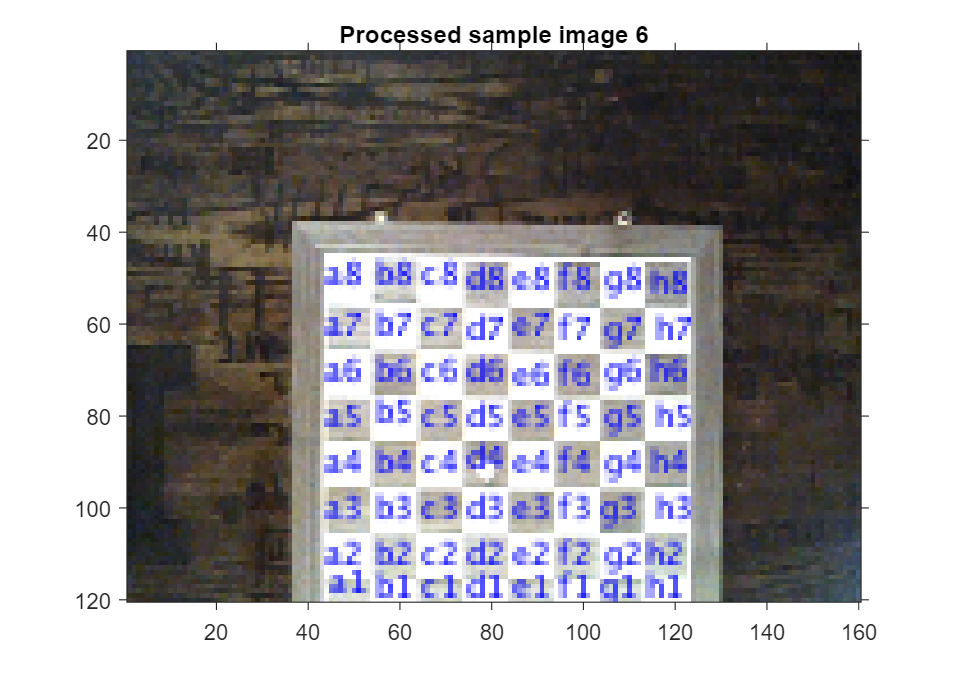

outputImage = chessboardProcessor(chessboardwithpawnd4_2(:, :, 1), chessboardwithpawnd4_2(:, :, 2), chessboardwithpawnd4_2(:, :, 3));
imshow(outputImage);
title('Processed sample image 6');

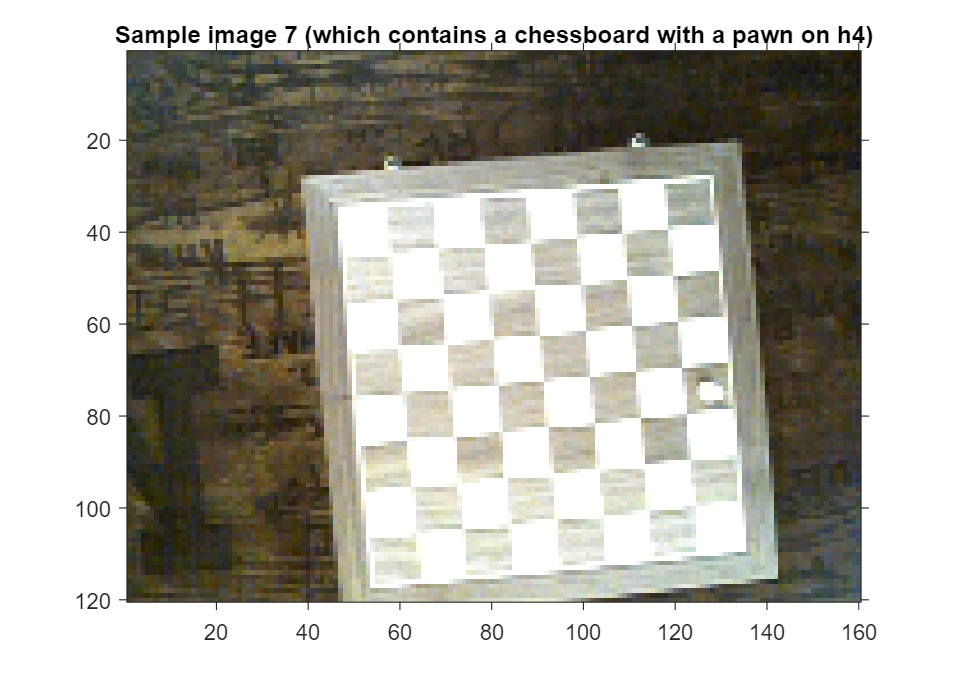


imshow(chessboardwithpawnh4_1)
title('Sample image 7 (which contains a chessboard with a pawn on h4)');

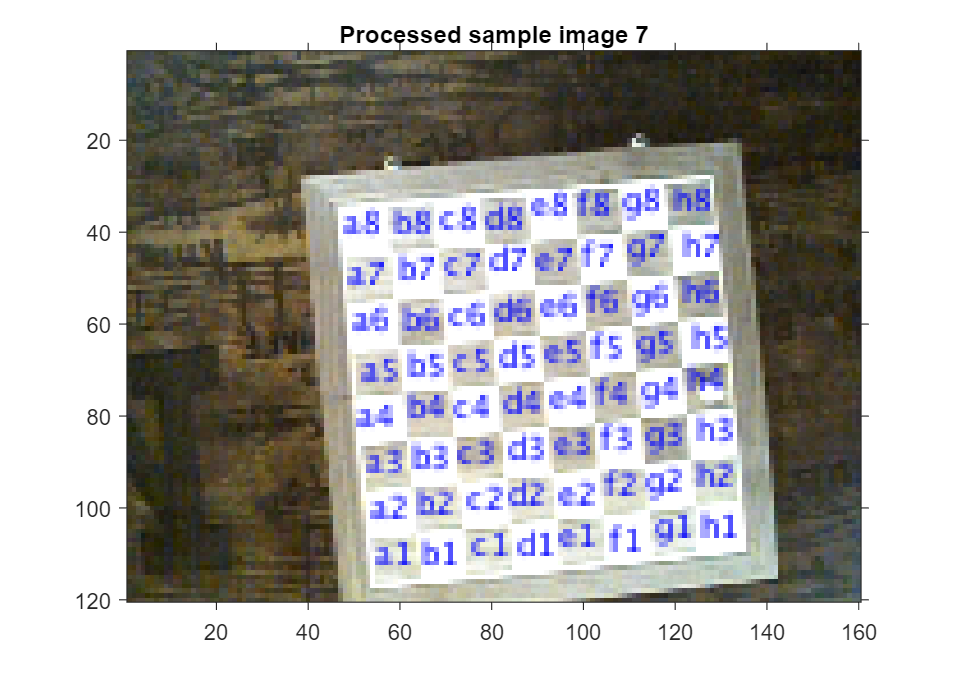

outputImage = chessboardProcessor(chessboardwithpawnh4_1(:, :, 1), chessboardwithpawnh4_1(:, :, 2), chessboardwithpawnh4_1(:, :, 3));
imshow(outputImage);
title('Processed sample image 7');

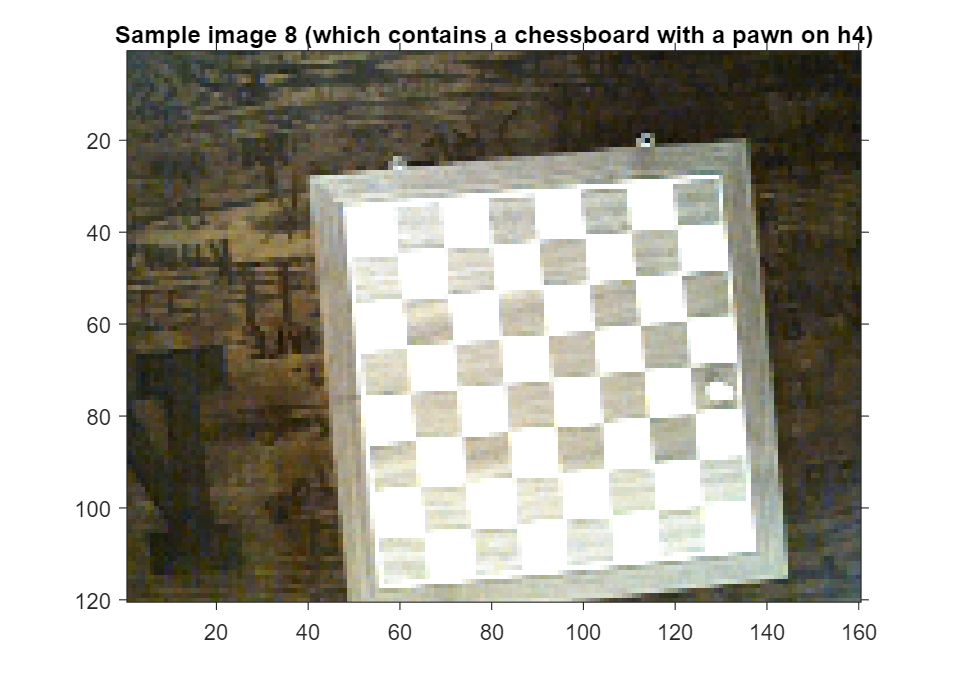


imshow(chessboardwithpawnh4_2);
title('Sample image 8 (which contains a chessboard with a pawn on h4)');

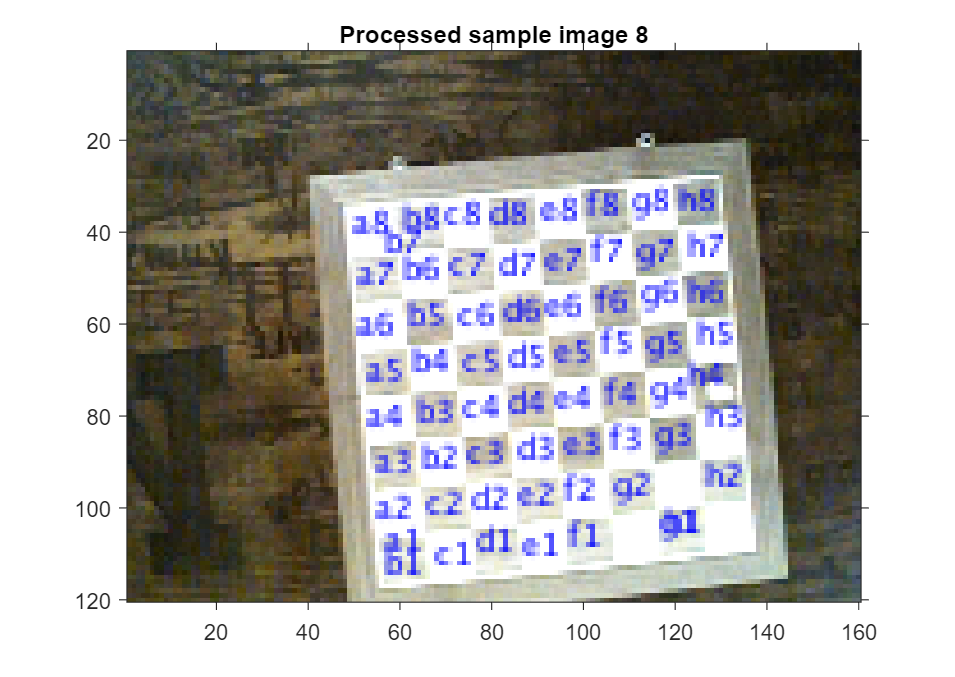

outputImage = chessboardProcessor(chessboardwithpawnh4_2(:, :, 1), chessboardwithpawnh4_2(:, :, 2), chessboardwithpawnh4_2(:, :, 3));
imshow(outputImage);
title('Processed sample image 8');

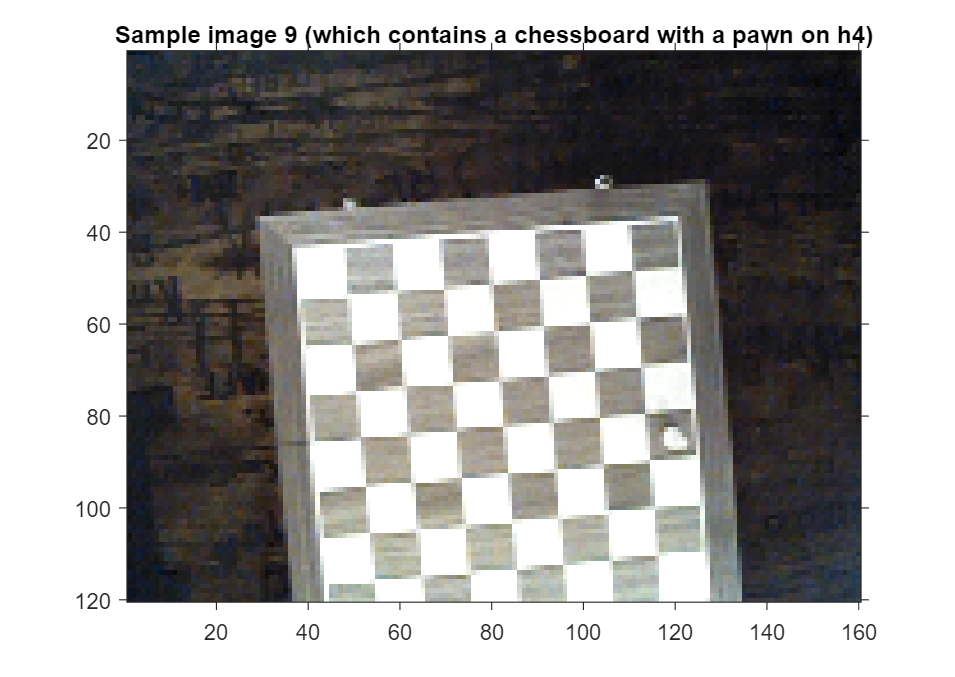


imshow(chessboardwithpawnh4_3);
title('Sample image 9 (which contains a chessboard with a pawn on h4)');

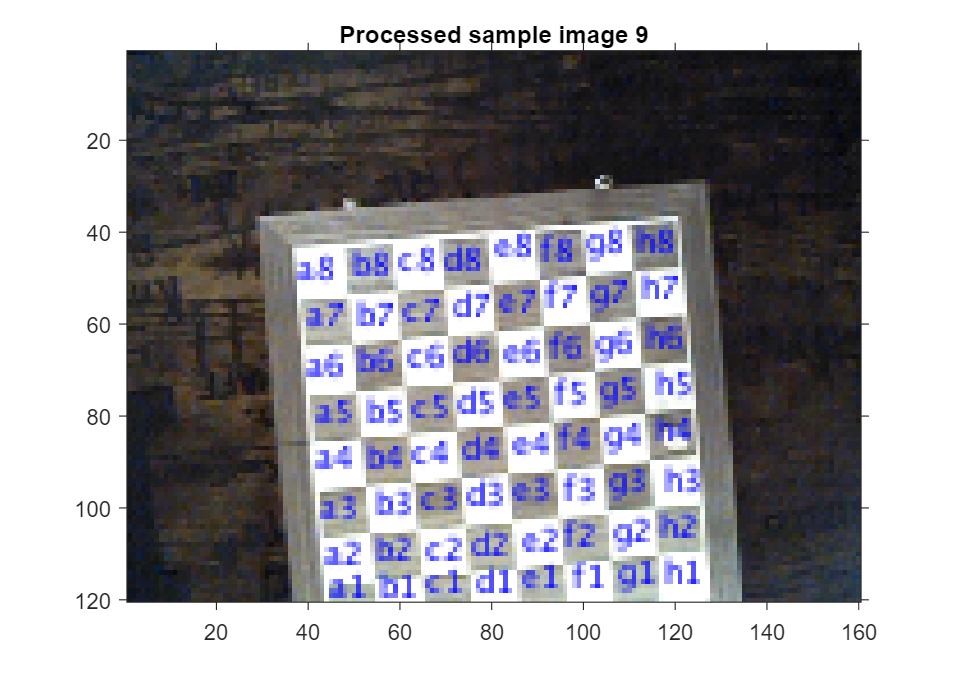

outputImage = chessboardProcessor(chessboardwithpawnh4_3(:, :, 1), chessboardwithpawnh4_3(:, :, 2), chessboardwithpawnh4_3(:, :, 3));
imshow(outputImage);
title('Processed sample image 9');

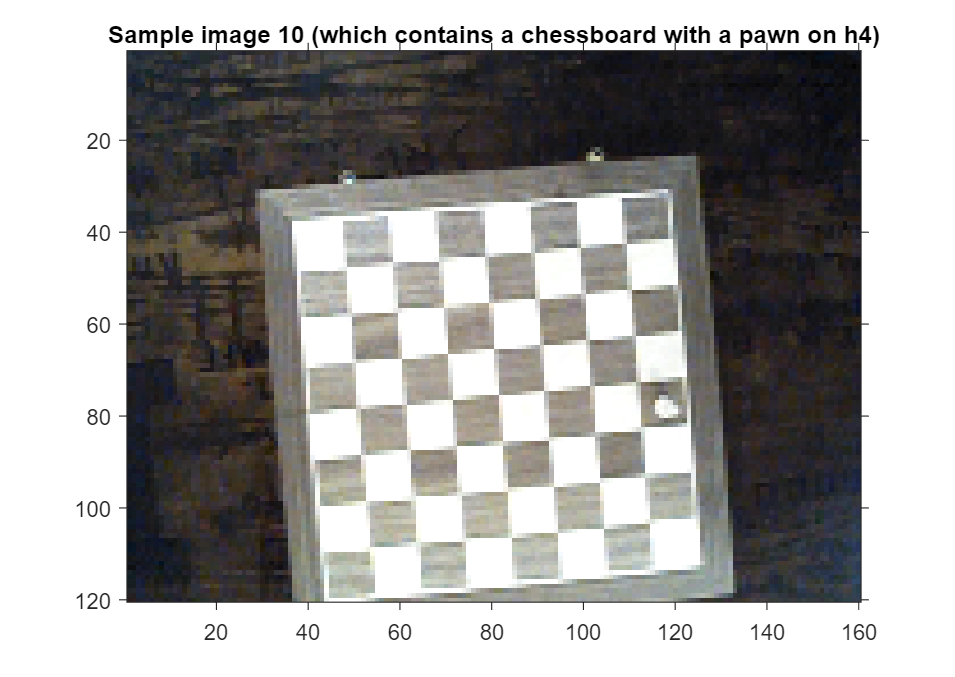


imshow(chessboardwithpawnh4_4);
title('Sample image 10 (which contains a chessboard with a pawn on h4)');

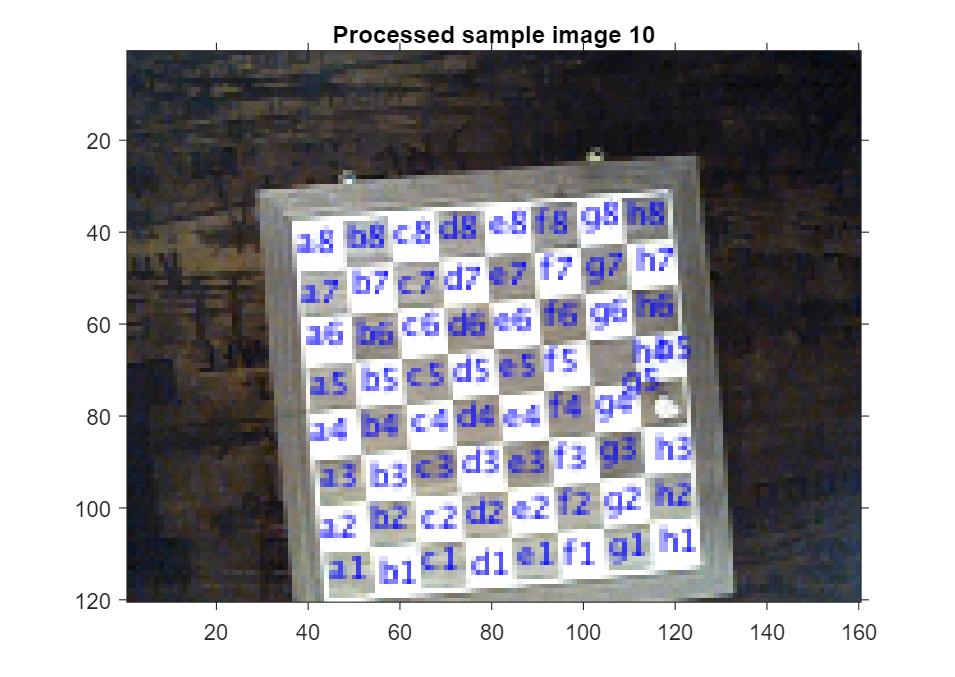

outputImage = chessboardProcessor(chessboardwithpawnh4_4(:, :, 1), chessboardwithpawnh4_4(:, :, 2), chessboardwithpawnh4_4(:, :, 3));
imshow(outputImage);
title('Processed sample image 10');

function [chessboardPixelsBW, chessboardPixelsGray] = chessboardSegmenter(R, G, B)

    % input: three 120x160 uint8 arrays R, G, and B
    % output: a 120x160 logical array chessboardPixelsBW indicating where the chessboard is in the image
    %         represented by R, G, and B and a 120x160 uint8 array chessboardPixelsGray showing the
    %         chessboard in grayscale (with black background) which can be used in future processing steps

    RGB = cat(3, R, G, B);
    gray = rgb2gray(RGB);
    adjustedGray = imadjust(gray);
    thresholdIntensity = round(mean(adjustedGray, 'all') - (1 / 2) * std(double(adjustedGray(:)), 0, 'all'));
    chessboardPixelsBW = adjustedGray > thresholdIntensity;
    
    chessboardPixelsBW = imfill(chessboardPixelsBW, 'holes');
    estimatedSquareWidth = round(sqrt(regionprops(bwpropfilt(chessboardPixelsBW, 'Area', 1), 'Area').Area) / 9);
    chessboardPixelsBW = imopen(chessboardPixelsBW, strel('square', estimatedSquareWidth));
    chessboardPixelsBW = bwpropfilt(chessboardPixelsBW, 'Area', 1);
    chessboardPixelsGray = adjustedGray .* uint8(chessboardPixelsBW);

end

function chessboardSquaresPixelsGray = chessboardSquaresSegmenter(chessboardPixelsGray)

    % input: a 120x160 grayscale image
    % output: a 120x160 grayscale image showing only the squares of the chessboard in the input image
    %         (assuming the input image contains a chessboard)

    edgeDetectionResult = edge(chessboardPixelsGray, 'canny');
    edgeDetectionResult = bwmorph(edgeDetectionResult, 'bridge');
    outerBoundary = bwpropfilt(edgeDetectionResult, 'ConvexArea', 1);
    middlePart = edgeDetectionResult - outerBoundary;
    chessboardSquaresPixelsBW = imclose(middlePart, strel('square', 160));
    chessboardSquaresPixelsGray = uint8(chessboardSquaresPixelsBW) .* chessboardPixelsGray;

end

function [all64Squares, all64SquaresStats] = getIndividualChessSquares(chessboardSquaresPixelsGray)

    % input: a 120x160 grayscale image
    % output: a 120x160 binary image of all 64 squares of the chessboard in the input image and
    %         a 64x2 table containing the Centroid and BoundingBox information of the 64 squares

    if sum(chessboardSquaresPixelsGray, 'all') == 0
        all64Squares = chessboardSquaresPixelsGray;
        all64SquaresStats = [];
        return;
    end

    boundaryPixels = edge(imbinarize(chessboardSquaresPixelsGray, 0), 'sobel');
    if sum(boundaryPixels, 'all') == 0
        all64Squares = chessboardSquaresPixelsGray;
        all64SquaresStats = [];
        return;
    end
    estimatedPerimeter = regionprops(boundaryPixels, 'Perimeter').Perimeter;
    estimatedSquareWidth = estimatedPerimeter / 4 / 8;

    thresholdIntensity = [250, 240, 230, 220, 210, 200];
    for i = 1 : size(thresholdIntensity, 2)
        detectedLightSquares = chessboardSquaresPixelsGray > thresholdIntensity(i);
        lightSquaresWithBorder = detectedLightSquares;
        lightSquaresWithBorder(boundaryPixels) = 1;
        lightSquaresBorderedAndConnected = bwmorph(lightSquaresWithBorder, 'bridge');
        lightSquaresBorderedAndConnected = imclose(lightSquaresBorderedAndConnected, strel('square', round(estimatedSquareWidth / 3)));
        distanceTransform = rescale(bwdist(~ lightSquaresBorderedAndConnected, 'chessboard'));
        squareBoundaries = distanceTransform > 0 & distanceTransform < 0.3;
        squareBoundaries(boundaryPixels) = 1;
        squareBoundaries = imclose(squareBoundaries, strel('square', round(estimatedSquareWidth / 3)));
        squareBoundaries = bwmorph(squareBoundaries, 'diag');
        allIndividualSquares = imcomplement(squareBoundaries) & imfill(squareBoundaries, 'holes');
        allIndividualSquaresStats = regionprops('table', allIndividualSquares, 'Centroid', 'BoundingBox');
        if size(allIndividualSquaresStats, 1) == 64
            all64Squares = allIndividualSquares;
            all64SquaresStats = allIndividualSquaresStats;
            return;
        end
    end
    all64Squares = zeros(size(chessboardSquaresPixelsGray));
    all64SquaresStats = [];
end

function labeledImage = labelCoordinates(R, G, B, all64SquaresStats)

    % input: three 120x160 uint8 arrays R, G, and B and a 64x2 table containing the Centroid and BoundingBox
    %        information of the 64 squares in the image represented by the R, G, and B arrays
    % output: a 120x160x3 uint8 array representing the image with the labeled coordinates of the chess squares in the image

    all64SquaresStats.x = all64SquaresStats.Centroid(:, 1);
    all64SquaresStats.y = all64SquaresStats.Centroid(:, 2);
    all64SquaresStats = sortrows(all64SquaresStats, 'x');
    
    for i = 1 : size(all64SquaresStats, 1)
        all64SquaresStats{i, 'x'} = idivide(i - 1, int8(8));
    end

    all64SquaresStats = sortrows(all64SquaresStats, ["x", "y"], ["ascend", "descend"]);
    
    for i = 1 : size(all64SquaresStats, 1)
        all64SquaresStats{i, 'y'} = mod(i - 1, 8);
    end

    ranks = ["a", "b", "c", "d", "e", "f", "g", "h"];
    files = ["1", "2", "3", "4", "5", "6", "7", "8"];
    coordinates = strings(8);
    for i = 1 : 8
        for j = 1 : 8
            coordinates(j, i) = ranks(i) + files(j);
        end
    end
    
    all64SquaresStats.Coordinates = coordinates(:);
    
    originalImage = cat(3, R, G, B);
    labeledImage = insertText(originalImage, all64SquaresStats.Centroid, ...
                              all64SquaresStats.Coordinates, 'BoxOpacity', 0, ...
                              'TextColor', 'blue', 'AnchorPoint', 'Center', 'FontSize', 7);

end

function processedImage = chessboardProcessor(R, G, B)

    % input: three 120x160 uint8 arrays R, G, and B
    % output: a 120x160x3 uint8 array representing the processed image of our chessboard coordinates determination algorithm

    [~, chessboardPixelsGray] = chessboardSegmenter(R, G, B);
    
    chessboardSquaresPixelsGray = chessboardSquaresSegmenter(chessboardPixelsGray);
    
    [~, all64SquaresStats] = getIndividualChessSquares(chessboardSquaresPixelsGray);

    if ~ isempty(all64SquaresStats)
        processedImage = labelCoordinates(R, G, B, all64SquaresStats);
    else
        processedImage = uint8(zeros(size(R, 1), size(R, 2), 3));
    end

end